# Representational Similarity Analysis for Sun et al., 2026

Michael Sun, Ph.D.

## Housekeeping

Note that the analysis requires the use of CANLabCore Tools to be downloaded in a Matlab working directory.

% Check if CanlabCore Tools are installed
toolboxName = 'CANLab Core'; % Replace with the actual toolbox name
functionName = 'fmri_data'; % Replace with a function or file name from the toolbox

% Check if the function or file associated with the toolbox exists
if exist(functionName, 'file') == 2
    fprintf('%s is installed.\n', toolboxName);
else
    fprintf('%s is not installed.\n', toolboxName);
end

CANLab Core is installed.


% 1) Check that RSA Toolbox is installed
% ----------------------------------------------------
if isempty(what('rsa'))
    error(['RSA Toolbox not found.\n' ...
           'Required functions rankTransform() and squareRDM() are missing.\n' ...
           'Please add the RSA Toolbox to your MATLAB path:\n' ...
           '   addpath(genpath(''path/to/RSAtoolbox''))']);
end

## Load Data

Load the .mat file.

load("RSM_Workspace.mat");

Td = run_data.metadata_table;
sub = string(Td.subjectid); tr = string(Td.condition); bs = string(Td.body_site);
rid = strcat(sub,'|',string(double(Td.session)),'|',string(double(Td.run)));   % unique run
clz = @(x) atanh(min(max(x,-0.999),0.999));
subs = unique(sub); nS = numel(subs);
svgdir = fullfile(pwd, 'figures_svg');
if ~exist(svgdir,'dir'), mkdir(svgdir); end

## Data

### Run Data Metadata

disp(run_data.metadata_table)

    subjectid    condition    body_site     session    run    repetition    temp    intensity_rating    valence_rating    comfort_rating
    _________    _________    __________    _______    ___    __________    ____    ________________    ______________    ______________

        1         hot         Left Face        2        2         1           48         34.074              -12.84           41.914    
        1         hot         Left Face        4        3         2           48         35.864             -23.457           47.346    
        1         hot         Left Face        6        4         3           48          50.37             -38

**RSM_3D_fixed: **These are the 9 (subject) 24 x 24 (condition) Spearman's representational similarity matrices constructed from run_data used to conduct the RSA analysis.

disp(size(RSM_3D_fixed));

    24    24     9



## WHOLE-BRAIN run-clean RSM (cross-run Spearman; exclude same-run pairs)

rg = run_data;
Xr = tiedrank(double(rg.dat));
Rcln = nan(24,24,nS); cBS = strings(24,nS); cTR = strings(24,nS); ck = strcat(bs,'|',tr);
for s = 1:nS
    imgs = find(sub==subs(s)); [uc,~,gc] = unique(ck(imgs));
    for a = 1:numel(uc)
        ii = imgs(gc==a); cBS(a,s)=bs(ii(1)); cTR(a,s)=tr(ii(1));
        for b = 1:numel(uc)
            jj = imgs(gc==b); M = corr(Xr(:,ii), Xr(:,jj));
            Rcln(a,b,s) = mean(clz(M(rid(ii) ~= rid(jj)')), 'omitnan');
        end
    end
end

bsO=["Left Face","Right Face","Left Arm","Right Arm","Left Leg","Right Leg","Chest","Abdomen"];
trO=["hot","warm","imagine"]; canon=strings(24,1); z=0;
for a=1:3, for b=1:8, z=z+1; canon(z)=bsO(b)+"|"+trO(a); end, end
Rord=nan(24,24,nS);
for s=1:nS, key=cBS(:,s)+"|"+cTR(:,s); [~,pos]=ismember(canon,key); Rord(:,:,s)=Rcln(pos,pos,s); end
xl=repmat({'L','R','L','R','L','R','Chest','Abd.'},1,3);   % publication tick labels

## Figure 7A: Group Level Representational Similarity Matrix

Cell order: [Left Face,Right Face,Left Arm,Right Arm,Left Leg,Right Leg,Chest,Abdomen] x [Hot, Warm, Imagine]

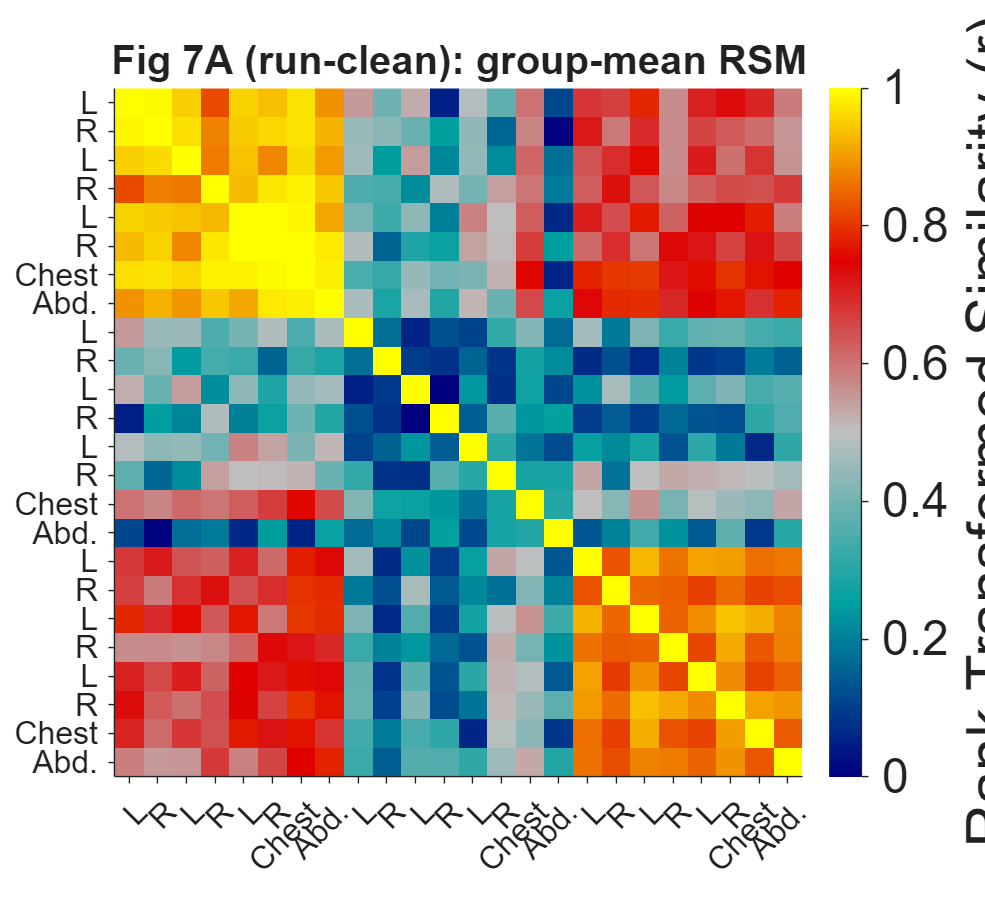

% Fig 7A: group-mean RSM in publication style (rank-transformed, RDMcolormap) via showRSM
figure('Color','w','Position',[0 0 900 820]); showRSM(mean(Rord,3,'omitnan'));
xticks(1:24); yticks(1:24); xticklabels(xl); yticklabels(xl); xtickangle(45);
ax=gca; ax.FontSize=16; title('Fig 7A (run-clean): group-mean RSM','FontSize',20);
print(gcf, fullfile(svgdir, 'Figure_7A_GroupRSM.svg'), '-dsvg', '-vector');   % vector SVG export

## Figure 7B: Subject Level Representational Similarity Matrix

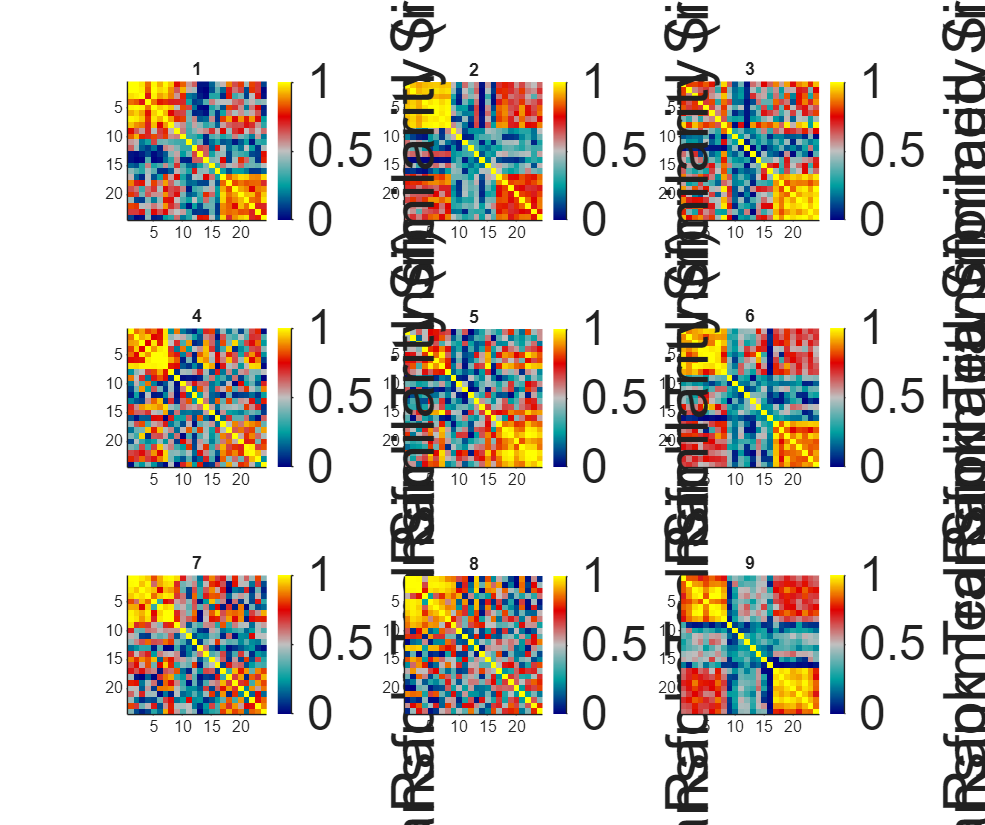

% Fig 7B: per-subject RSMs, same publication style
figure('Color','w','Position',[0 0 1290 1080]);
for s=1:nS, subplot(3,3,s); showRSM(Rord(:,:,s)); title(subs(s),'Interpreter','none'); ax=gca; ax.FontSize=8; end
print(gcf, fullfile(svgdir, 'Figure_7B_SubjectRSMs.svg'), '-dsvg', '-vector');   % vector SVG export

## Figure 7C: Design RSM

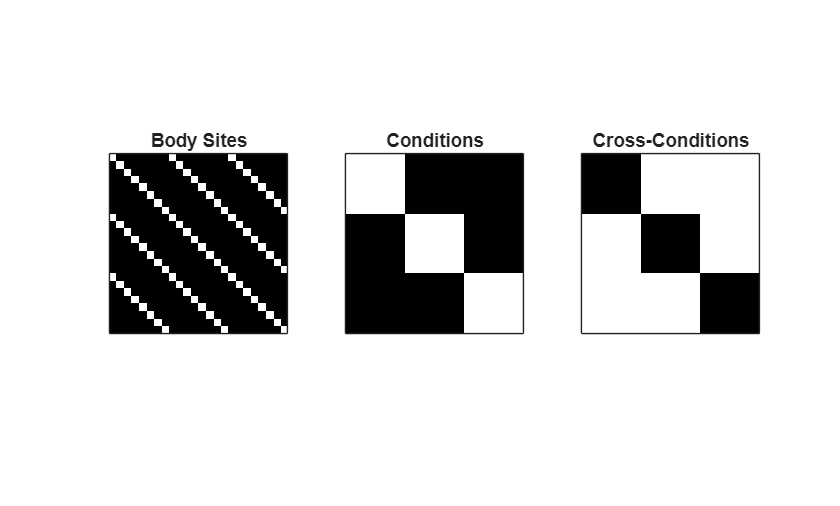

figure; 
colormap(gray)
subplot(1,3,1)
imagesc(DesignRSMs.Bodysite);
title('Body Sites')
xticklabels('')
yticklabels('')
% Remove all ticks from both axes
set(gca, 'XTick', [], 'YTick', []);
% Make the plot perfectly square
axis equal tight;

subplot(1,3,2)
imagesc(DesignRSMs.Condition);
title('Conditions')
xticklabels('')
yticklabels('')
% Remove all ticks from both axes
set(gca, 'XTick', [], 'YTick', []);
% Make the plot perfectly square
axis equal tight;

subplot(1,3,3)
imagesc(DesignRSMs.CrossCondition);
title('Cross-Conditions')
xticklabels('')
yticklabels('')
% Remove all ticks from both axes
set(gca, 'XTick', [], 'YTick', []);
% Make the plot perfectly square
axis equal tight;
print(gcf, fullfile(svgdir, 'Figure_7C_DesignRSMs.svg'), '-dsvg', '-vector');   % vector SVG export

## Figure 7D-F: Body Site, Condition, Cross-Condition barplots

Col   1: Hot	Col   2: Warm	Col   3: Imagine	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
       Name        Mean_Value    Std_Error       T           P         Cohens_d
    ___________    __________    __________    ______    __________    ________

    {'Hot'    }     0.060354       0.013746    4.3906     0.0023157     1.4635 
    {'Warm'   }    0.0053312     0.00098659    5.4036    0.00064321     1.8012 
    {'Imagine'}     0.049507       0.010682    4.6346     0.0016779     1.5449 



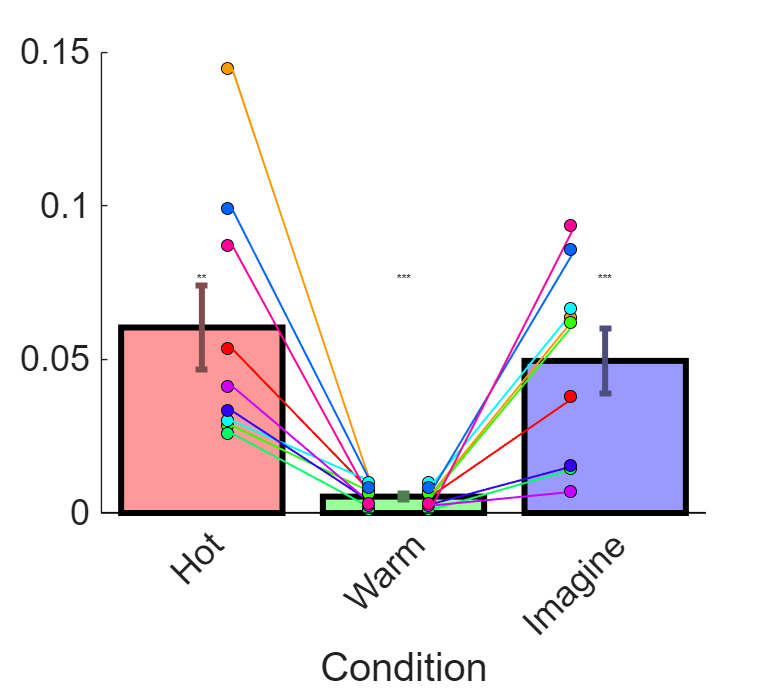

Col   1: Hot-Warm	Col   2: Hot-Imagine	Col   3: Imagine-Warm	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
          Name          Mean_Value    Std_Error      T           P         Cohens_d
    ________________    __________    _________    ______    __________    ________

    {'Hot-Warm'    }     0.011454     0.0021428    5.3453    0.00068971     1.7818 
    {'Hot-Imagine' }     0.025811     0.0067214    3.8401     0.0049467       1.28 
    {'Imagine-Warm'}    0.0083859     0.0019831    4.2287     0.0028815     1.4096 



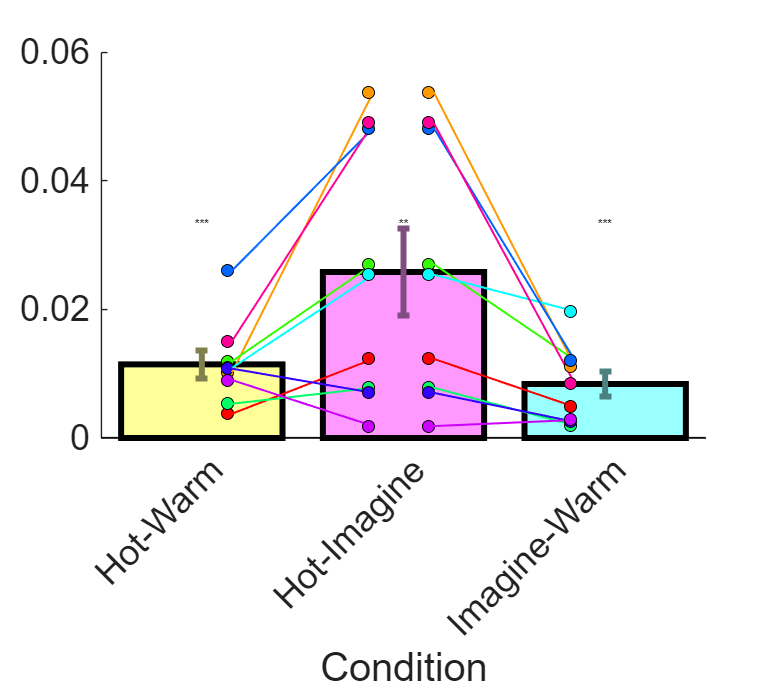

Col   1: Same bodysite	Col   2: Diff bodysite	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
          Name           Mean_Value    Std_Error      T           P        Cohens_d
    _________________    __________    _________    ______    _________    ________

    {'Same bodysite'}     0.017223     0.0035705    4.8238    0.0013149     1.6079 
    {'Diff bodysite'}     0.022753     0.0044762     5.083    0.0009496     1.6943 



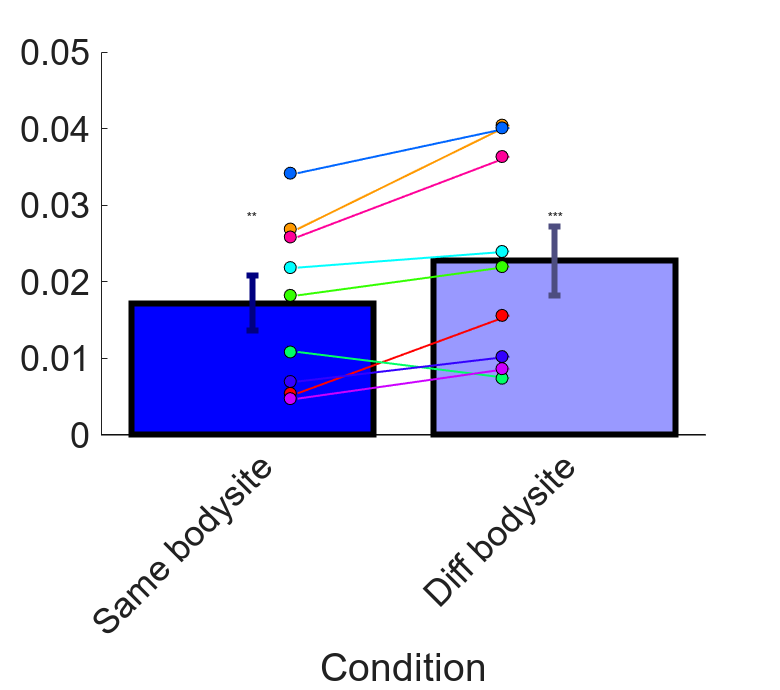

blk=@(M,t,ta,tb) mean(M((t==ta)&(t==tb)'&~eye(24)),'omitnan');
sbf=@(M,b) mean(M((b==b')&~eye(24)),'omitnan'); dbf=@(M,b) mean(M((b~=b')&~eye(24)),'omitnan');
C=nan(nS,8);
for s=1:nS
    Mc=Rcln(:,:,s); t=cTR(:,s); b=cBS(:,s);
    C(s,:)=[blk(Mc,t,"hot","hot") blk(Mc,t,"warm","warm") blk(Mc,t,"imagine","imagine") blk(Mc,t,"hot","warm") blk(Mc,t,"hot","imagine") blk(Mc,t,"imagine","warm") sbf(Mc,b) dbf(Mc,b)];
end

sets={ {[1 2 3],{'Hot','Warm','Imagine'},{[1 .6 .6],[.6 1 .6],[.6 .6 1]},'Fig 7D within-condition','RC_Fig7D_withinCondition'};
       {[4 5 6],{'Hot-Warm','Hot-Imagine','Imagine-Warm'},{[1 1 .6],[1 .6 1],[.6 1 1]},'Fig 7E cross-condition','RC_Fig7E_crossCondition'};
       {[7 8],{'Same bodysite','Diff bodysite'},{[0 0 1],[.6 .6 1]},'Fig 7F bodysite','RC_Fig7F_bodysite'} };
scol = hsv(nS+1); scol = scol([1:2,4:end],:);    % per-subject colors (drop green), pub plot_roi style
for i=1:numel(sets)
    figure('Color','w','Position',[0 0 520 460]);
    dd = arrayfun(@(k) C(:,k), sets{i}{1}, 'uni', 0);
    % bhand=barplot_columns(dd,'names',sets{i}{2},'color',sets{i}{3},'nofig','noviolin','noind','pairwisetest');
    bhand=barplot_columns(dd,'names',sets{i}{2},'color',sets{i}{3},'nofig','noviolin','noind');
    for jj=1:numel(bhand.bar_han), try, bhand.bar_han{jj}.LineWidth=3; bhand.bar_han{jj}.EdgeColor=[0 0 0]; catch, end, end   % bold, thick outlines
    hold on; plotWithinGroup(dd, sets{i}{2}, 'IndColors', scol, 'PlotHalfViolin', false, 'PlotBox', false);
    hline(0,'k-'); 
    % ylabel('Fisher r-to-z (cross-run)'); 
    ylabel(''); 
    % title(sets{i}{4}+" (run-clean)"); 
    title(""); 
    % xtickangle(20);
    % saveas(gcf,outdir+sets{i}{5}+".png");
    print(gcf, fullfile(svgdir, [sets{i}{5},'.svg']), '-dsvg', '-vector');   % vector SVG export
end

## PARCELWISE run-clean — region codes (131-region pain-pathways atlas)

load(af,'canlab2024_2'); labs=canlab2024_2.labels; nR=numel(labs);
atlg = resample_space(canlab2024_2, rg);
fullcode = zeros(prod(rg.volInfo.dim(1:3)),1); fullcode(atlg.volInfo.wh_inmask)=round(double(atlg.dat(:,1)));
codesD = fullcode(rg.volInfo.wh_inmask);
if numel(codesD)~=size(rg.dat,1), codesD=codesD(~rg.removed_voxels); end

subImg=arrayfun(@(s) find(sub==subs(s)),1:nS,'uni',0); V=nan(nR,nS,8);
for r=1:nR
    rows=find(codesD==r); if isempty(rows), continue; end
    Dr=double(rg.dat(rows,:));
    for s=1:nS
        ii=subImg{s}; Cimg=corr(Dr(:,ii),'type','Spearman'); c=tr(ii); b=bs(ii); rr=rid(ii);
        ag=@(Mk) mean(clz(Cimg(Mk)),'omitnan');
        V(r,s,:)=[ag((c=="hot")&(c=="hot")'&(b~=b')) ag((c=="warm")&(c=="warm")'&(b~=b')) ag((c=="imagine")&(c=="imagine")'&(b~=b')) ...
                  ag((c=="hot")&(c=="warm")'&(rr~=rr')) ag((c=="hot")&(c=="imagine")'&(rr~=rr')) ag((c=="imagine")&(c=="warm")'&(rr~=rr')) ...
                  ag((b==b')&(c~=c')&(rr~=rr')) ag((b~=b')&(c~=c'))];
    end
end

% Region t-maps for all contrasts (+ survival + region names)

con={'HI_HW',5,4,'Hot-Imagine > Hot-Warm (Fig 7G/S9)';
    'HI_IW',5,6,'Hot-Imagine > Imagine-Warm'; ...
    'HW_IW',4,6,'Hot-Warm > Imagine-Warm';
    'Hot_Warm',1,2,'Hot vs Warm (within-cond)'; ...
     'Imagine_Warm',3,2,'Imagine vs Warm (within-cond)';
     'sameBS_diffBS',7,8,'Same > Different bodysite';
     'Hot_Imagine',1,3,'Hot vs Imagine (within-cond)'};
Tall=nan(nR,size(con,1)); Pall=nan(nR,size(con,1));

## Figure 7G

bright_colormap = [linspace(.5,1,256)', linspace(.5,1,256)', zeros(256,1)];
dark_colormap   = flipud([linspace(0.1,1,256)', zeros(256,1), linspace(0.1,1,256)']);

## Directional contrasts + FDR (one-tailed: hypothesis is imagined MORE like experienced pain)

HI = squeeze(V(:,:,5)); HW = squeeze(V(:,:,4)); IW = squeeze(V(:,:,6));

pHW = nan(nR,1); tHW = nan(nR,1); pIW = nan(nR,1); tIW = nan(nR,1);
for r = 1:nR
    d1 = HI(r,:)-HW(r,:); d1 = d1(~isnan(d1)); if numel(d1)>=3, [~,~,~,s]=ttest(d1); tHW(r)=s.tstat; [~,pHW(r)]=ttest(d1,0,'tail','right'); end
    d2 = HI(r,:)-IW(r,:); d2 = d2(~isnan(d2)); if numel(d2)>=3, [~,~,~,s]=ttest(d2); tIW(r)=s.tstat; [~,pIW(r)]=ttest(d2,0,'tail','right'); end
end
fHW = pHW <= bh(pHW,.05); 
fIW = pIW <= bh(pIW,.05); 

## FDR-gated conjunction: both uncorrected < thr AND >=1 arm FDR-corrected

mint = min(tHW,tIW); 
avgt = mean([tHW,tIW], 2);

atLeast1 = fHW | fIW;

Keeping vals between 0.000 and 1000000.000: 79249 voxels in .sig
Compressed NIfTI files are not supported.


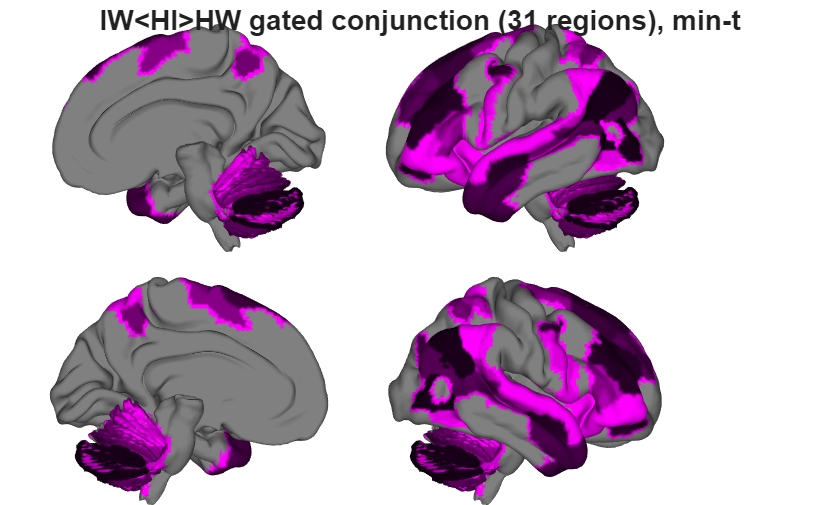

cm   = flipud([linspace(0.1,1,256)', zeros(256,1), linspace(0.1,1,256)']);
render_map(set31, mint, canlab2024_2, cm, 'hcp', fullfile(svgdir,"RC_Fig7G_gated31_surface.png"), 'IW<HI>HW gated conjunction (31 regions), min-t');

## Figure 7G Barplots

rois={'SII+','SMA', 'BA47', 'hippocampal_formation'};
labs=canlab2024_atlas.labels; 
scolG = hsv(nS+1); scolG = scolG([1:2,4:end],:);   % per-subject colors (drop green), pub plot_roi style
figure('Color','w','Position',[0 0 1500 700]);
for i=1:numel(rois)
    ri=find(strcmp(labs,rois{i}),1); subplot(2,2,i); if isempty(ri), title([rois{i} ' n/a']); continue; end
    dd={squeeze(V(ri,:,4))',squeeze(V(ri,:,5))',squeeze(V(ri,:,6))'};
    % bhand=barplot_columns(dd,'names',{'HW','HI','IW'},'color',{[1 1 .6],[1 .6 1],[.6 1 1]},'nofig','noviolin','noind','pairwisetest');
    bhand=barplot_columns(dd,'names',{'HW','HI','IW'},'color',{[1 1 .6],[1 .6 1],[.6 1 1]},'nofig','noviolin','noind');
    for jj=1:numel(bhand.bar_han), try, bhand.bar_han{jj}.LineWidth=3; bhand.bar_han{jj}.EdgeColor=[0 0 0]; catch, end, end   % bold, thick outlines
    hold on; plotWithinGroup(dd,{'HW','HI','IW'},'IndColors',scolG,'PlotHalfViolin',false,'PlotBox',false);
    % [~,pp,~,st]=ttest(squeeze(V(ri,:,5)),squeeze(V(ri,:,4)),'tail','right'); hline(0,'k-'); ylabel('r-to-z');
    % title(sprintf('%s \n(HI>HW t=%.2f p=%.3g)',char(format_strings_for_legend(rois{i})),st.tstat,pp));
    title(sprintf('%s',char(format_strings_for_legend(rois{i}))));
end

Col   1: HW	Col   2: HI	Col   3: IW	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
     Name     Mean_Value    Std_Error      T           P        Cohens_d
    ______    __________    _________    ______    _________    ________

    {'HW'}     0.036651     0.0077018    4.7588     0.001429     1.5863 
    {'HI'}     0.026699      0.006636    4.0234    0.0038228     1.3411 
    {'IW'}    0.0059911     0.0022948    2.6107     0.031097    0.87023 

Col   1: HW	Col   2: HI	Col   3: IW	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
     Name     Mean_Value    Std_Error      

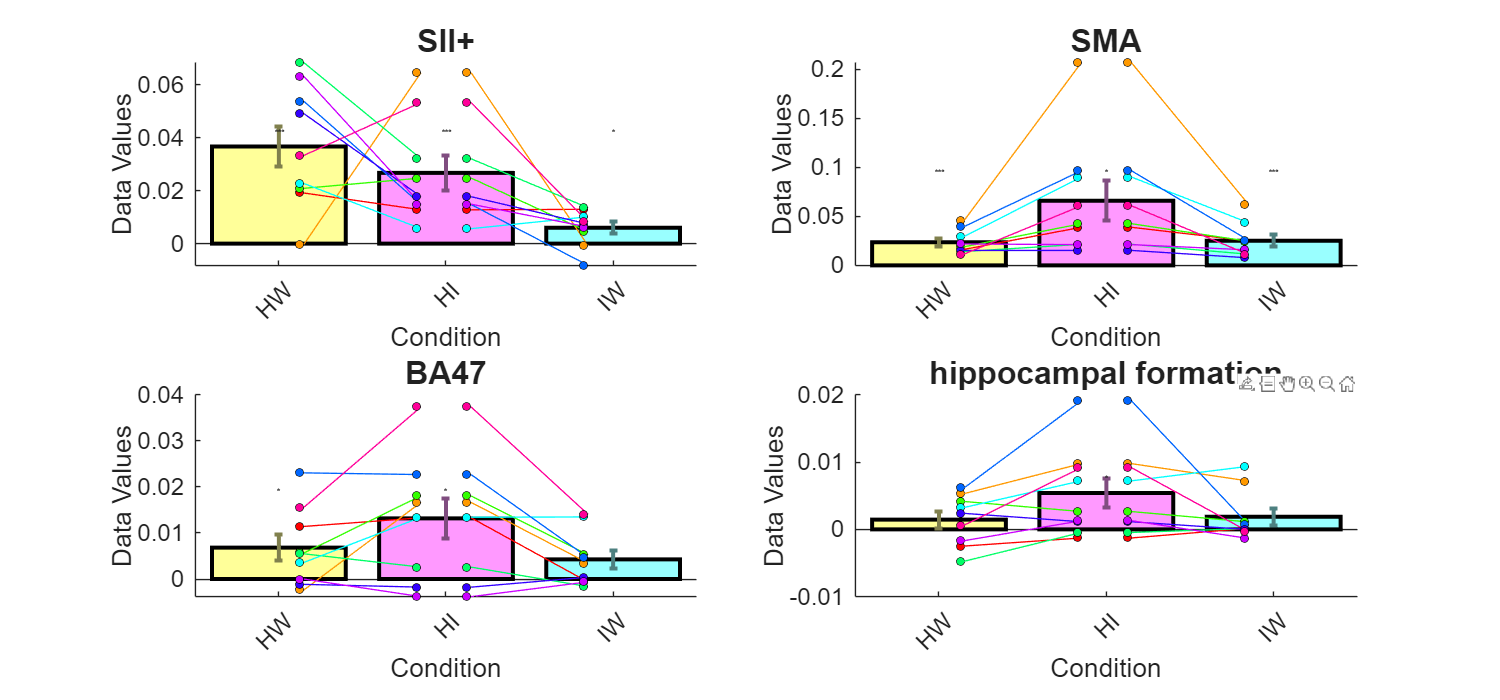

print(gcf, fullfile(svgdir, 'RC_Fig7G_barplots.svg'), '-dsvg', '-vector');   % vector SVG export

## Supplemental Figure 10 Barplots Numbered-dot + numbered-legend format for HI-HW, HI-IW (2D) and HI/HW/IW (3D)

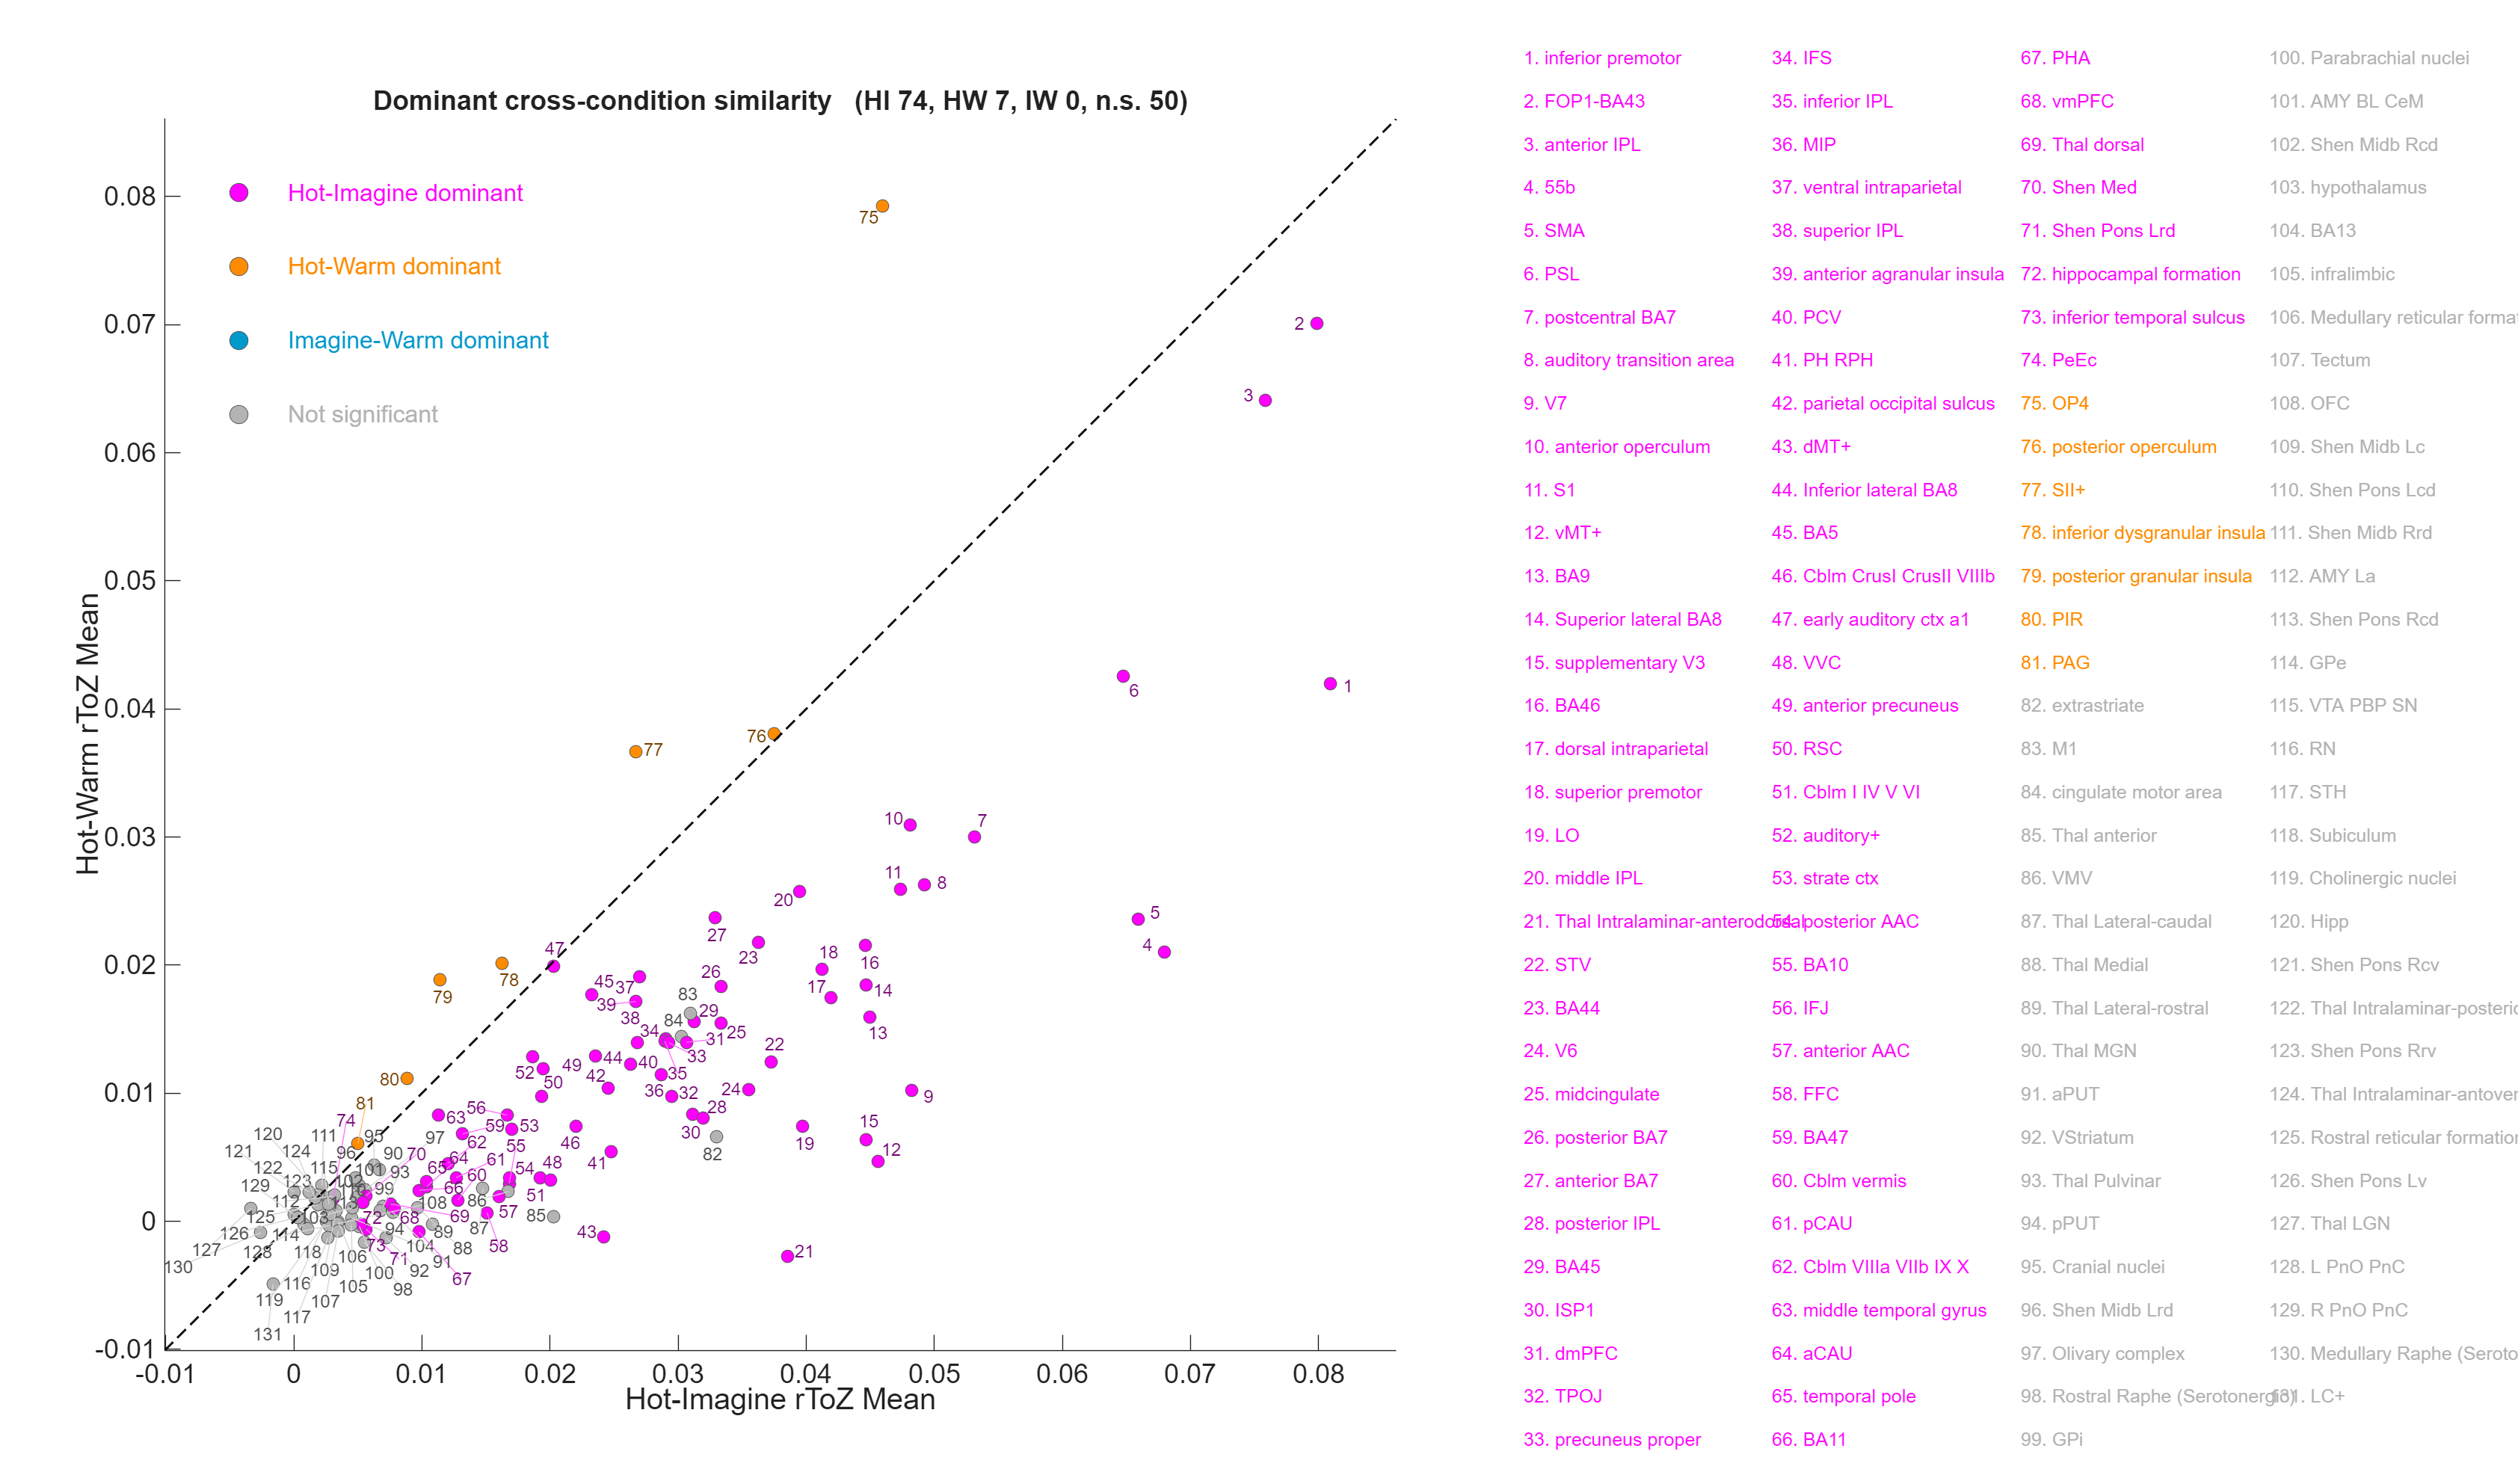

%% Numbered-dot + legend, colored by SIGNIFICANT dominant cross-condition correlation
% expects V, labs, nR, outdir already in scope
Vc=V(:,:,[5 4 6]);                                            % 1=HI 2=HW 3=IW
mn=squeeze(mean(Vc,2,'omitnan')); [mx,win]=max(mn,[],2);      % dominant pairing per region
pdom=ones(nR,1);                                             % p of the DOMINANT correlation vs 0 (one-tailed)
for r=1:nR, x=squeeze(Vc(r,:,win(r))); x=x(~isnan(x)); if numel(x)>=3, [~,pdom(r)]=ttest(x,0,'tail','both'); end, end
sig = pdom<0.05;                                            % uncorrected p<.05

cg=win; cg(~sig)=4;                                          % color group: 1=HI 2=HW 3=IW 4=n.s.
S.cols=[1 0 1; 1 0.55 0; 0 0.6 0.8; 0.7 0.7 0.7];            % magenta / orange / teal / gray
S.knames={'Hot-Imagine dominant','Hot-Warm dominant','Imagine-Warm dominant','Not significant'};
% S.FN='Helvetica Neue Light'; 
S.win=cg; S.nR=nR;
S.FN='Helvetica';
S.lbl=cellfun(@(x) char(format_strings_for_legend(x)), labs(:), 'uni', 0);
[~,ord]=sortrows([cg -mx]); S.num=zeros(nR,1); S.num(ord)=1:nR;
S.nstr=arrayfun(@(k) sprintf('%d',k), S.num, 'uni', 0);
S.ttl=sprintf('Dominant cross-condition similarity   (HI %d, HW %d, IW %d, n.s. %d)',sum(cg==1),sum(cg==2),sum(cg==3),sum(cg==4));

HIm=mean(V(:,:,5),2,'omitnan'); HWm=mean(V(:,:,4),2,'omitnan'); IWm=mean(V(:,:,6),2,'omitnan');
make2d(HIm,HWm,'Hot-Imagine rToZ Mean','Hot-Warm rToZ Mean', fullfile(svgdir, "RC_FigS8_numbered_HIvsHW.svg"), S);

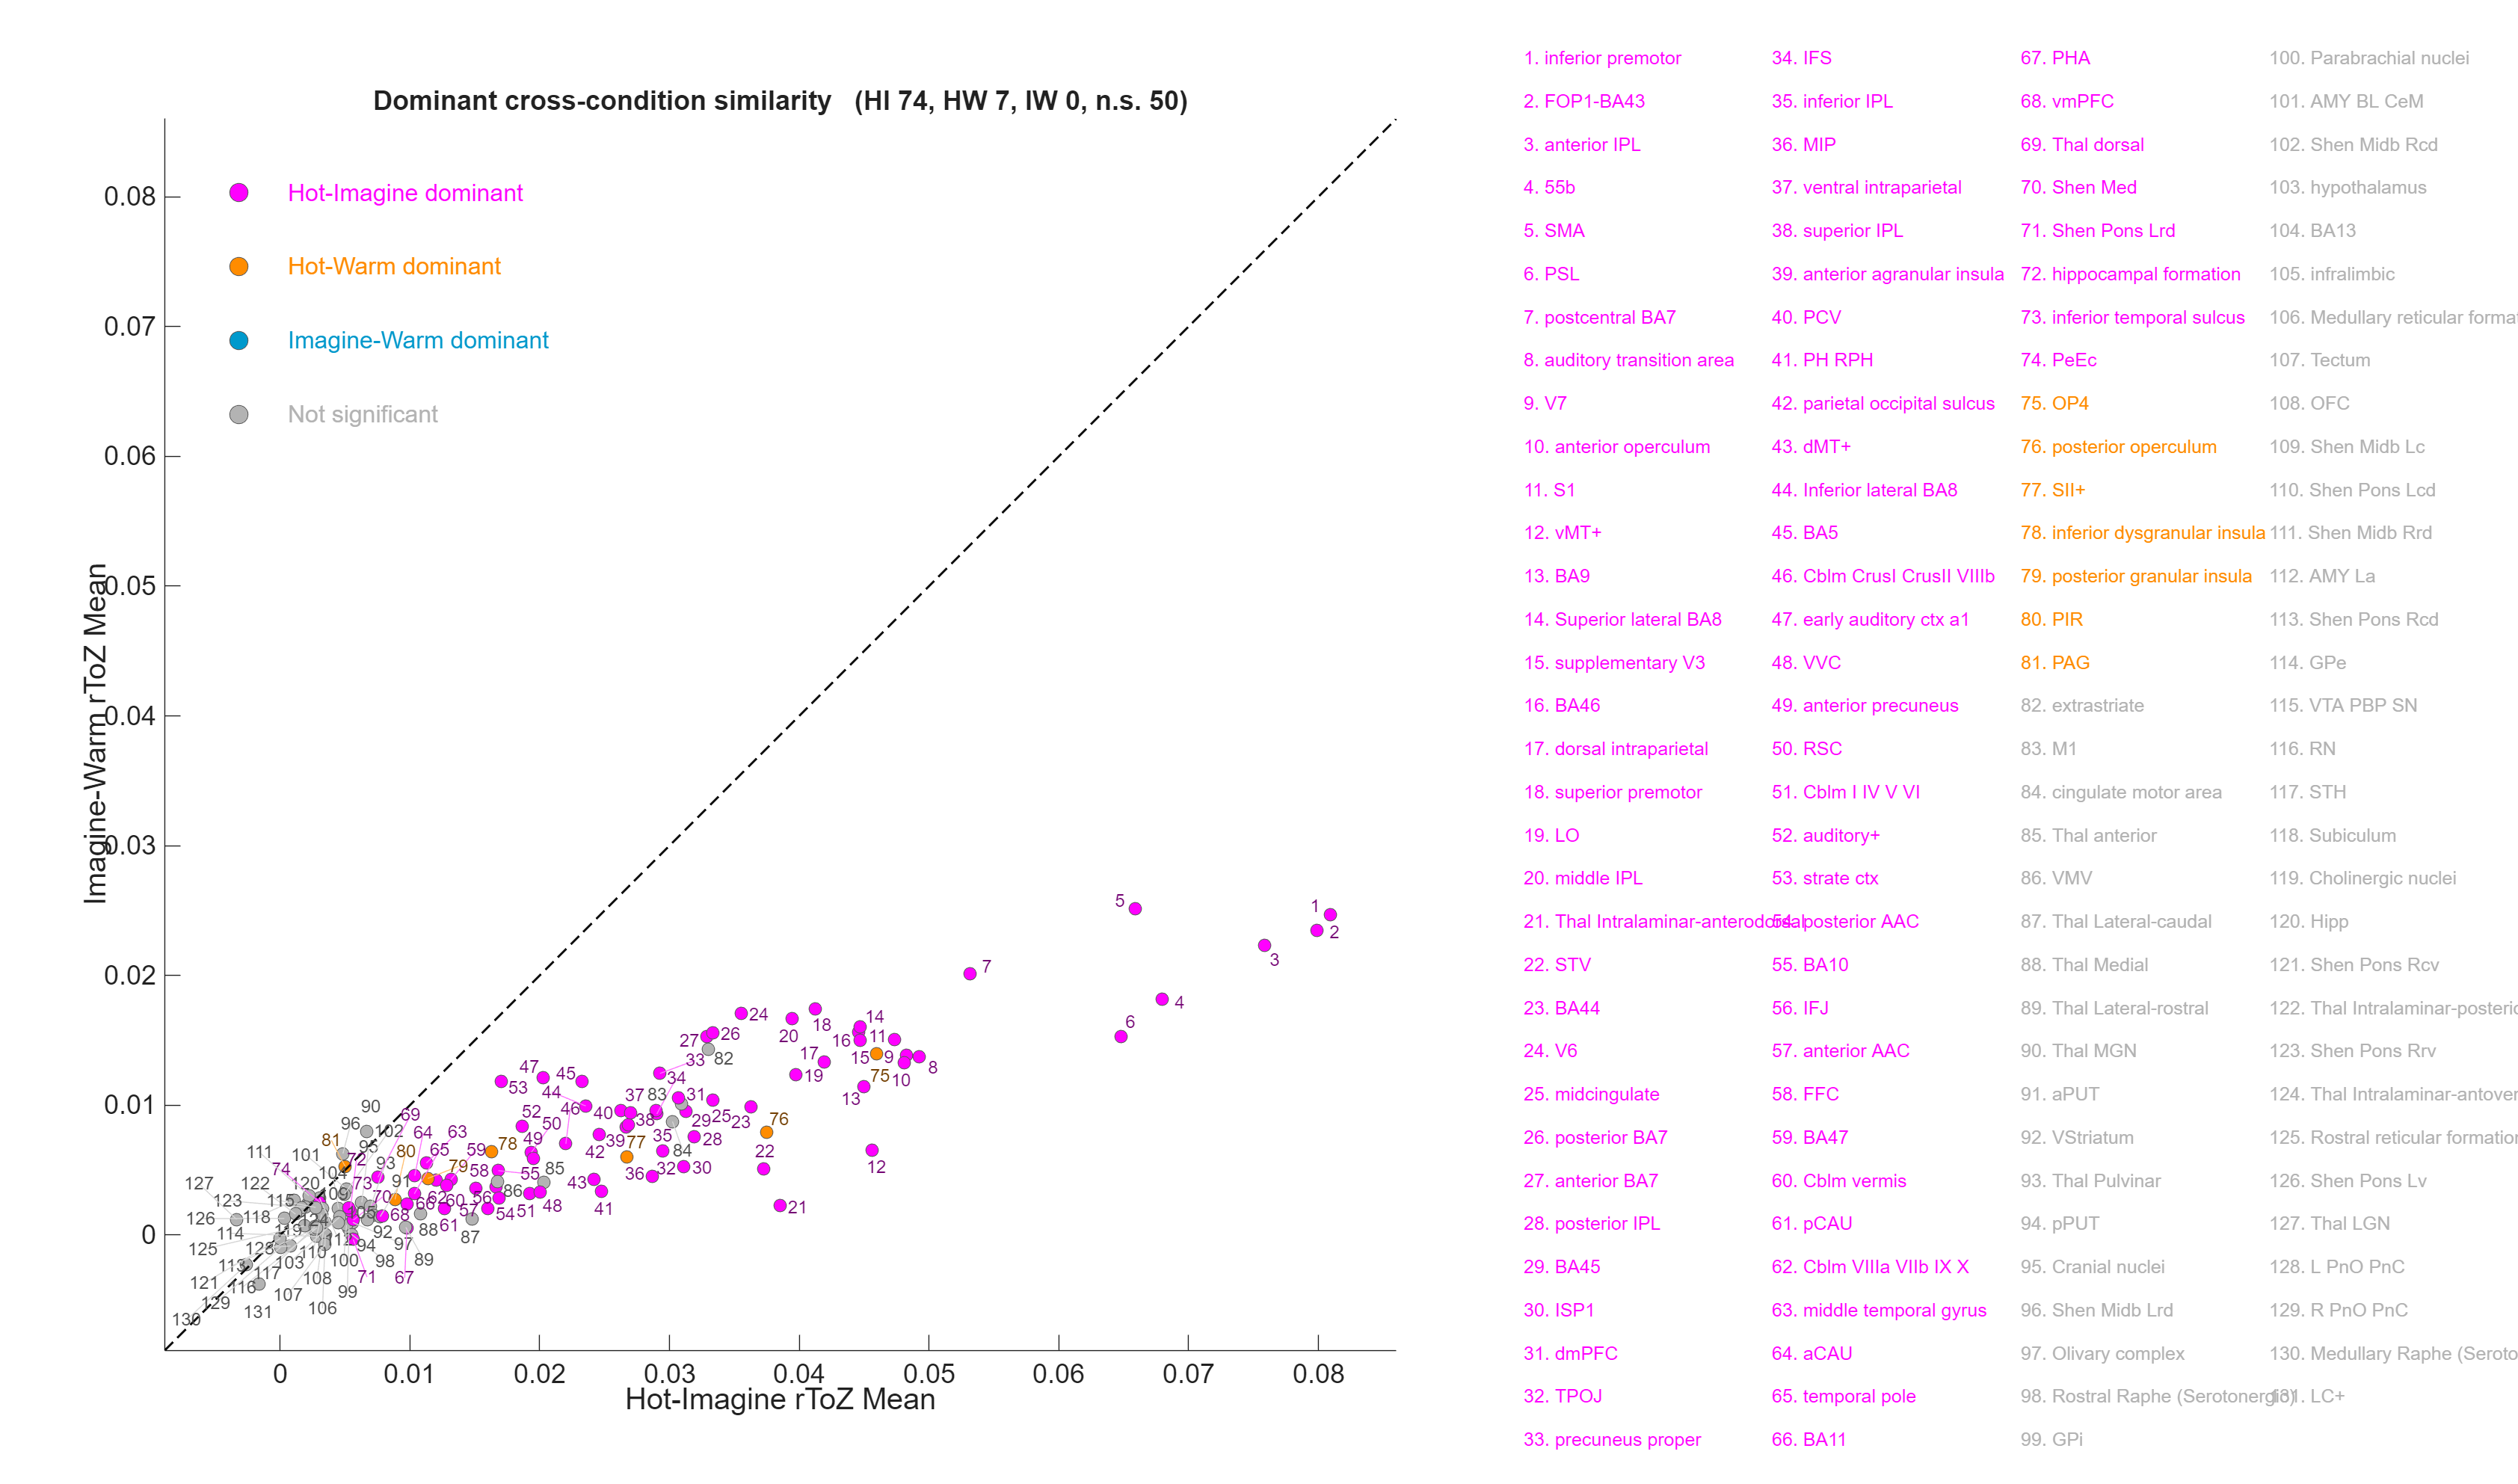

make2d(HIm,IWm,'Hot-Imagine rToZ Mean','Imagine-Warm rToZ Mean',fullfile(svgdir, "RC_FigS8_numbered_HIvsIW.svg"), S);

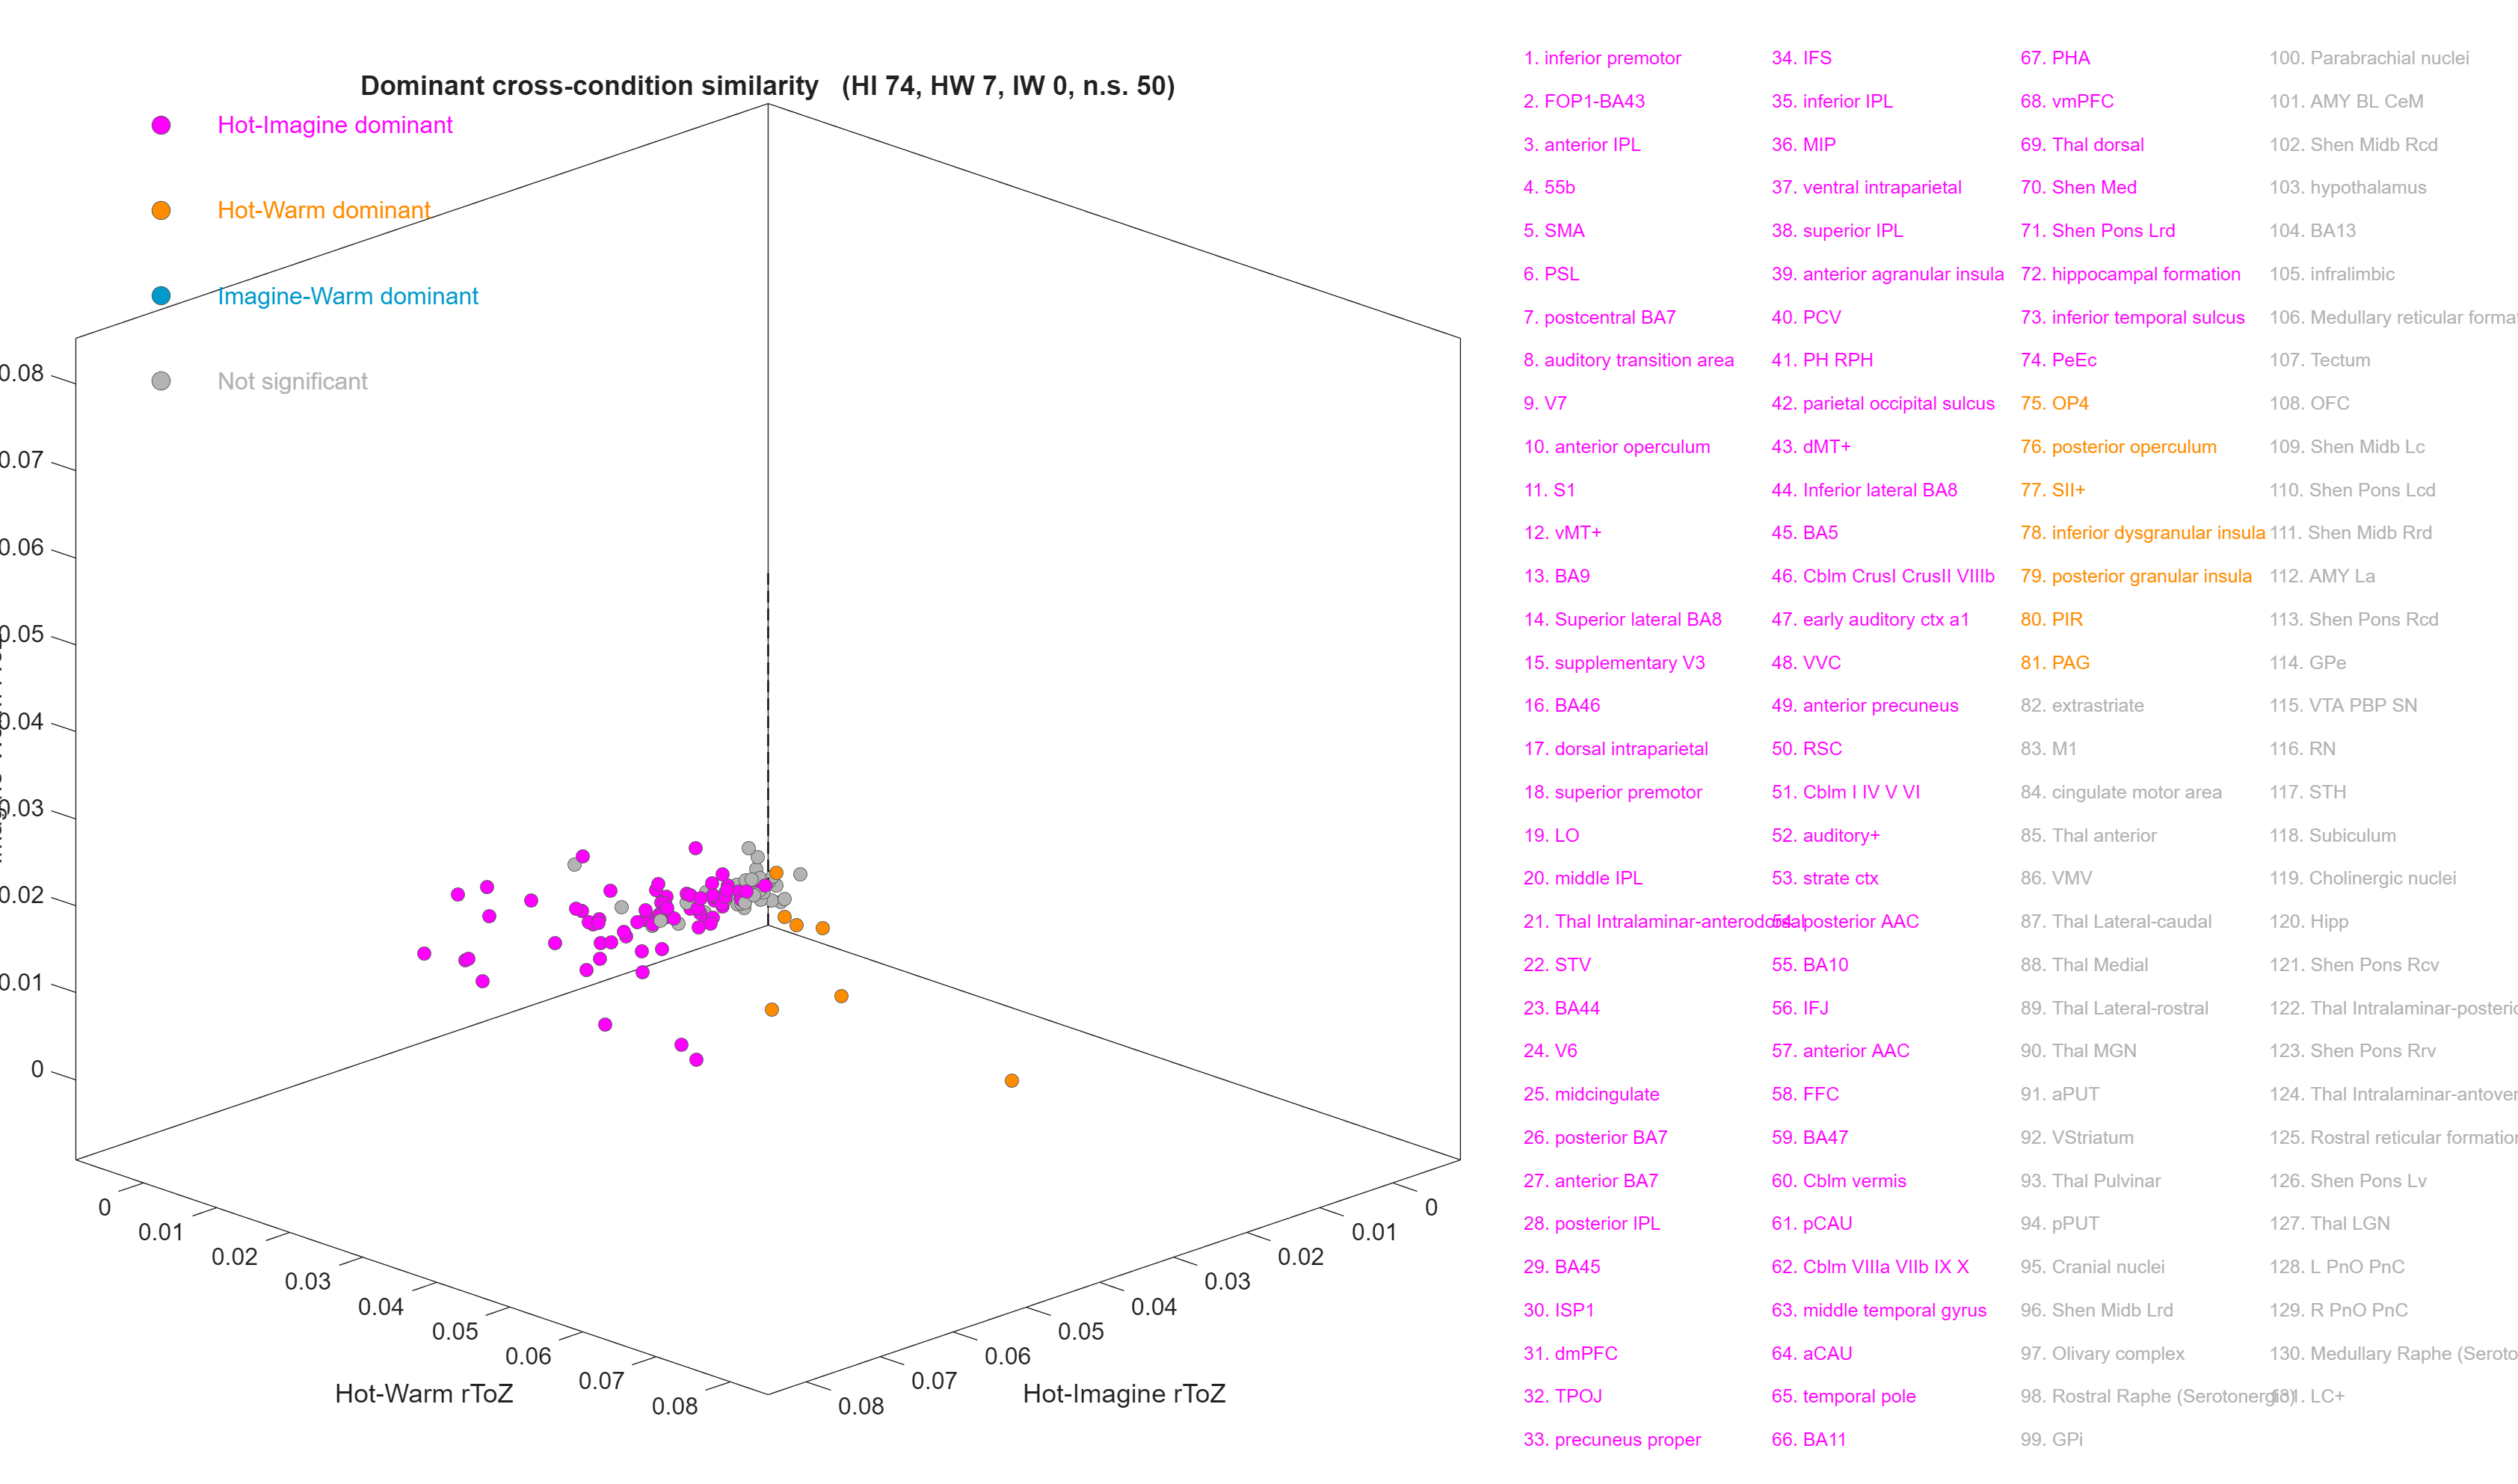

make3d(HIm,HWm,IWm,                                             fullfile(svgdir, "RC_FigS8_numbered_3D.svg"),    S);


function make2d(xd,yd,xlab,ylab,fname,S)
FN=S.FN; cols=S.cols; win=S.win; num=S.num; lbl=S.lbl; nstr=S.nstr; nR=S.nR; nk=numel(S.knames); Cd=cols(win,:);
figure('Color','w','Position',[0 0 2800 1650]);
p=[0.05 0.09 0.52 0.83]; axS=axes('Position',p); hold(axS,'on');
scatter(axS,xd,yd,70,Cd,'filled','MarkerEdgeColor',[.35 .35 .35]);
dl=[min([xd;yd]) max([xd;yd])]; pad=0.06*range(dl); dl=[dl(1)-pad dl(2)+pad];
xlim(axS,dl); ylim(axS,dl); daspect(axS,[1 1 1]); plot(axS,dl,dl,'k--','LineWidth',1.4);
xlabel(axS,xlab); ylabel(axS,ylab); set(axS,'FontName',FN,'FontSize',18); box(axS,'off');
title(axS,S.ttl,'FontName',FN,'FontSize',18);
fsN=12;
tmp=text(xd,yd,nstr,'Parent',axS,'FontSize',fsN,'FontName',FN,'HorizontalAlignment','center','VerticalAlignment','middle');
drawnow; E=cell2mat(get(tmp,'Extent')); delete(tmp); w=E(:,3)*1.22; h=E(:,4)*1.1;
koff=1.0*h;
lx=xd+0.004*range(dl)*randn(nR,1); ly=yd+0.004*range(dl)*randn(nR,1);
for it=1:1000
    for i=1:nR
        dx=lx(i)-lx; dy=ly(i)-ly; ox=(w(i)+w)/2-abs(dx); oy=(h(i)+h)/2-abs(dy);
        hit=ox>0 & oy>0; hit(i)=false; fx=0; fy=0;
        if any(hit), fx=sum(sign(dx(hit)+eps).*ox(hit)); fy=sum(sign(dy(hit)+eps).*oy(hit)); end
        ddx=lx(i)-xd; ddy=ly(i)-yd; dd=hypot(ddx,ddy)+eps; pushd=koff(i)-dd; hd=pushd>0;
        if any(hd), fx=fx+sum((ddx(hd)./dd(hd)).*pushd(hd)); fy=fy+sum((ddy(hd)./dd(hd)).*pushd(hd)); end
        fx=fx-0.02*(lx(i)-xd(i)); fy=fy-0.02*(ly(i)-yd(i));
        lx(i)=lx(i)+0.2*fx; ly(i)=ly(i)+0.2*fy;
    end
    lx=min(max(lx,dl(1)),dl(2)); ly=min(max(ly,dl(1)),dl(2));
end
for i=1:nR
    vx=lx(i)-xd(i); vy=ly(i)-yd(i); d=hypot(vx,vy);
    if d<koff(i), if d<eps, a=2*pi*rand; vx=cos(a); vy=sin(a); d=1; end
        lx(i)=xd(i)+vx/d*koff(i); ly(i)=yd(i)+vy/d*koff(i); end
end
for i=1:nR
    if hypot(lx(i)-xd(i),ly(i)-yd(i))>1.6*h(i)
        plot(axS,[xd(i) lx(i)],[yd(i) ly(i)],'-','Color',0.55*Cd(i,:)+0.45,'LineWidth',0.3);
    end
    text(axS,lx(i),ly(i),nstr{i},'FontSize',fsN,'FontName',FN,'Color',0.45*Cd(i,:),'HorizontalAlignment','center','VerticalAlignment','middle');
end
rg=range(dl); kx=dl(1)+0.06*rg; ky=dl(2)-0.06*rg;
for g=1:nk
    scatter(axS,kx,ky-(g-1)*0.06*rg,150,cols(g,:),'filled','MarkerEdgeColor',[.35 .35 .35]);
    text(axS,kx+0.04*rg,ky-(g-1)*0.06*rg,S.knames{g},'Color',cols(g,:),'FontSize',16,'FontName',FN,'VerticalAlignment','middle');
end
draw_legend(num,lbl,win,cols,FN,12.5,[0.605 0.02 0.395 0.95],nR);
% print(gcf,char(fname),'-dpng','-r200');
print(gcf, char(fname), '-dsvg', '-vector');   % vector SVG export
end

function make3d(xd,yd,zd,fname,S)
FN=S.FN; cols=S.cols; win=S.win; num=S.num; lbl=S.lbl; nR=S.nR; nk=numel(S.knames);
figure('Color','w','Position',[0 0 2800 1650]);
p=[0.03 0.06 0.55 0.87]; axS=axes('Position',p); hold(axS,'on'); view(axS,135,22); grid(axS,'on'); box(axS,'on');
for g=1:nk, sel=win==g; if any(sel), scatter3(axS,xd(sel),yd(sel),zd(sel),80,cols(g,:),'filled','MarkerEdgeColor',[.35 .35 .35]); end, end
lim=[min([xd;yd;zd]) max([xd;yd;zd])]; pad=0.05*range(lim); lim=[lim(1)-pad lim(2)+pad];
plot3(axS,lim,lim,lim,'k--','LineWidth',1.2); xlim(axS,lim); ylim(axS,lim); zlim(axS,lim);
grid off;
xlabel(axS,'Hot-Imagine rToZ'); ylabel(axS,'Hot-Warm rToZ'); zlabel(axS,'Imagine-Warm rToZ');
set(axS,'FontName',FN,'FontSize',16); title(axS,S.ttl,'FontName',FN,'FontSize',18);
draw_legend(num,lbl,win,cols,FN,12.5,[0.605 0.02 0.395 0.95],nR);
axk=axes('Position',[0.05 0.70 0.28 0.24],'XLim',[0 1],'YLim',[0 1],'Visible','off'); hold(axk,'on');
for g=1:nk
    scatter(axk,0.05,0.9-(g-1)*0.24,150,cols(g,:),'filled','MarkerEdgeColor',[.35 .35 .35]);
    text(axk,0.13,0.9-(g-1)*0.24,S.knames{g},'Color',cols(g,:),'FontSize',16,'FontName',FN,'VerticalAlignment','middle');
end
rotate3d(axS,'on');
% print(gcf,char(fname),'-dpng','-r200');
print(gcf, char(fname), '-dsvg', '-vector');   % vector SVG export
end

function draw_legend(num,lbl,win,cols,FN,fs,pos,nR)
axL=axes('Position',pos,'XLim',[0 1],'YLim',[0 1],'Visible','off'); hold(axL,'on');
[~,byNum]=sort(num); ncol=4; percol=ceil(nR/ncol); cx=linspace(0.0,0.75,ncol); yy=linspace(0.99,0.01,percol);
for a=1:nR
    i=byNum(a); ci=floor((a-1)/percol)+1; ri=mod(a-1,percol)+1;
    text(axL,cx(ci),yy(ri),sprintf('%d. %s',num(i),lbl{i}),'Color',cols(win(i),:),'FontSize',fs,'FontName',FN,'VerticalAlignment','middle','Interpreter','none');
end
end

## Supplemental Figure 10 (3D) — region-wise cross-condition similarity geometry in full (HI, HW, IW) space.

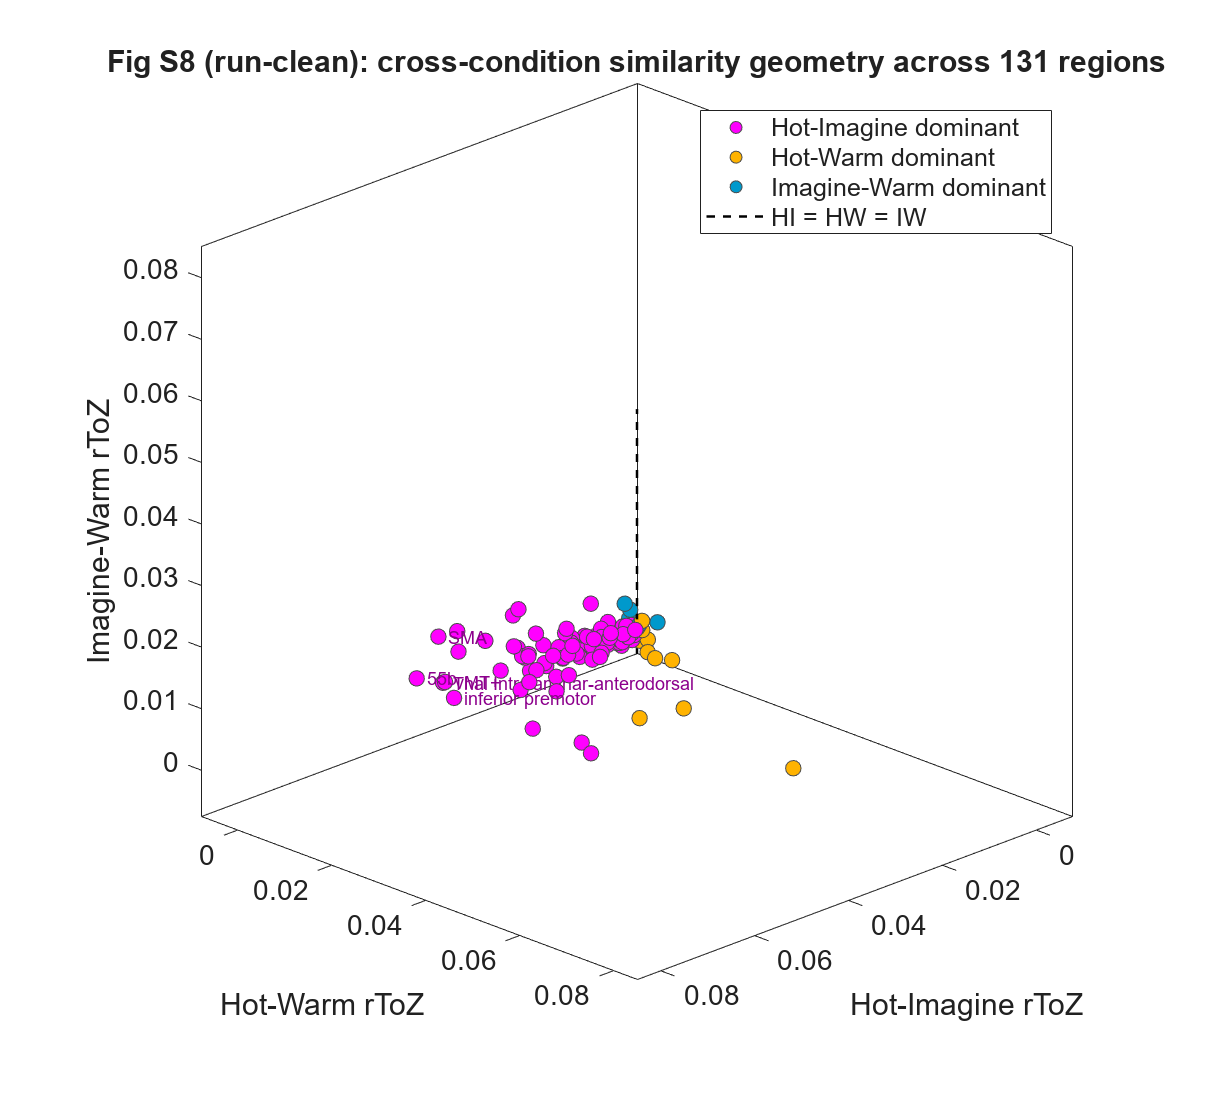

% Each region is one point; color = which pairing is most similar (argmax over the three).
% The HI-vs-HW and HI-vs-IW 2-D scatters are projections of this cube onto two faces.
HIm=mean(V(:,:,5),2,'omitnan'); HWm=mean(V(:,:,4),2,'omitnan'); IWm=mean(V(:,:,6),2,'omitnan');
Mreg=[HIm HWm IWm]; val=all(~isnan(Mreg),2); [~,win]=max(Mreg,[],2);   % 1=HI 2=HW 3=IW dominant
cmap=[1 0 1; 1 0.7 0; 0 0.6 0.8];                                      % HI magenta, HW amber, IW teal
figure('Color','w','Position',[0 0 940 840]); hold on; view(135,22); grid on; box on;
for g=1:3
    sel=(win==g)&val;
    scatter3(HIm(sel),HWm(sel),IWm(sel),60,cmap(g,:),'filled','MarkerEdgeColor',[.3 .3 .3]);
end
lim=[min(Mreg(val)) max(Mreg(val))]; pad=0.05*range(lim); lim=[lim(1)-pad lim(2)+pad];
plot3(lim,lim,lim,'k--','LineWidth',1.2);                             % identity line HI=HW=IW (no preference)
xlim(lim); ylim(lim); zlim(lim); axis square;
xlabel('Hot-Imagine rToZ'); ylabel('Hot-Warm rToZ'); zlabel('Imagine-Warm rToZ');
% label the strongest HI-dominant (imagined resembles experienced pain) regions
mrg=HIm-max(HWm,IWm); mrg(~val)=-Inf; [~,ord]=sort(mrg,'descend'); topN=ord(1:min(5,sum(val)));
for i=topN', text(HIm(i),HWm(i),IWm(i),['  ' char(format_strings_for_legend(labs{i}))], ...
        'Color',[.55 0 .55],'FontSize',9,'FontName','Helvetica'); end
legend({'Hot-Imagine dominant','Hot-Warm dominant','Imagine-Warm dominant','HI = HW = IW'},'Location','best');
title('Fig S8 (run-clean): cross-condition similarity geometry across 131 regions');
grid off;
set(gca,'FontName','Helvetica','FontSize',14); rotate3d on;
% saveas(gcf,outdir+"RC_FigS8_scatter3D.png");
drawnow
print(gcf, fullfile(svgdir, "RC_FigS8_scatter3D.svg"), '-dsvg', '-vector');   % vector SVG export

## Functions

function showRSM(RSM)
% showRSM  Plot a rank-transformed Representational Similarity Matrix.
%
%   showRSM(RSM)
%
%   RSM : square similarity matrix (conditions × conditions).
%
%   Requires rsa.rdm.* (rankTransform, squareRDM) and an RDMcolormap
%   defined in your path/workspace, or you can swap in your preferred
%   colormap.

    % Only import what you actually use
    import rsa.*
    import rsa.fig.*
    import rsa.fmri.*
    import rsa.rdm.*
    import rsa.sim.*
    import rsa.spm.*
    import rsa.stat.*
    import rsa.util.*

    % 1) Check that RSA Toolbox is installed
    % ----------------------------------------------------
    if isempty(what('rsa'))
        error(['RSA Toolbox not found.\n' ...
               'Required functions rankTransform() and squareRDM() are missing.\n' ...
               'Please add the RSA Toolbox to your MATLAB path:\n' ...
               '   addpath(genpath(''path/to/RSAtoolbox''))']);
    end

    % Rank-transform the RSM
    rankedRSM = rankTransform(squareRDM(RSM), 1);

    % Make sure the diagonal is exactly 1
    n = size(rankedRSM, 1);
    rankedRSM(1:n+1:end) = 1;   % fast way to set diagonal

    % Plot
    imagesc(rankedRSM, [0, 1]);
    colormap(RDMcolormap);      % assumes RDMcolormap is defined
    axis image;

    % Colorbar formatting
    cb = colorbar;
    cb.FontSize      = 24;
    cb.TickDirection = 'out';
    cb.Box           = 'off';
    ylabel(cb, 'Rank Transformed Similarity (r)', 'FontSize', 30);

    % Axes formatting
    ax = gca;
    ax.FontSize = 24;
    ax.TickDir  = 'out';
    ax.Box      = 'off';

    title('Representational Similarity Matrix', 'FontSize', 30);
end



function b = plot_bar_within(data, names, fills, indColors, varargin)
% plot_bar_within  barplot_columns + plotWithinGroup with consistent styling

p = inputParser;
p.addParameter('YLim', []);
p.addParameter('FaceAlpha', []);          % [] = do nothing
p.addParameter('DoPairwiseTest', true);
p.addParameter('WithinColors', []);       % optional: per-subject colors for within lines
p.parse(varargin{:});
opt = p.Results;

figure;
args = {'names', names, 'color', fills, 'noviolin', 'noind', 'nofig'};
if opt.DoPairwiseTest, args = [args {'pairwisetest'}]; end

b = barplot_columns(data, args{:});
hold on;

wgArgs = {'IndColors', indColors, 'PlotHalfViolin', false, 'PlotBox', false};
if ~isempty(opt.WithinColors)
    wgArgs = [wgArgs {'Colors', opt.WithinColors}];
end
plotWithinGroup(data, names, wgArgs{:});

hline(0,'k-');
ylabel('Fisher r-to-z');
xlabel('');
title('');
xtickangle(0);

% style bars
for k = 1:numel(b.bar_han)
    b.bar_han{k}.LineWidth = 3;
    if ~isempty(opt.FaceAlpha)
        b.bar_han{k}.FaceAlpha = opt.FaceAlpha;
    end
end

fontsize(13,'points');

if ~isempty(opt.YLim)
    ylim(opt.YLim);
end
end


function results = pairwise_stats_table(data, labels)
% pairwise_stats_table  Paired t-tests + mean±sd, mean diff, SE diff, d

mean_sd_n = @(x) [mean(x), std(x), numel(x)];

n = numel(labels);
pairs = nchoosek(1:n, 2);
nPairs = size(pairs,1);

Comparison         = strings(nPairs,1);
Mean_Difference    = nan(nPairs,1);
SE_Mean_Difference = nan(nPairs,1);
Mean_SD_Group1     = strings(nPairs,1);
Mean_SD_Group2     = strings(nPairs,1);
t_Statistic        = nan(nPairs,1);
p_Value            = nan(nPairs,1);
Cohens_d           = nan(nPairs,1);
Significance       = strings(nPairs,1);

for r = 1:nPairs
    i = pairs(r,1); j = pairs(r,2);

    x = data{i}; y = data{j};

    s1 = mean_sd_n(x);
    s2 = mean_sd_n(y);

    [~, p, ~, st] = ttest(x, y);   % paired

    % mean difference + SE of difference (paired): SE = std(x-y)/sqrt(n)
    dvec = x - y;
    mean_diff = mean(dvec);
    se_diff   = std(dvec) / sqrt(numel(dvec));

    % Cohen's dz for paired designs: mean(diff)/std(diff)
    dz = mean(dvec) / std(dvec);

    Comparison(r)         = labels{i} + " vs " + labels{j};
    Mean_Difference(r)    = mean_diff;
    SE_Mean_Difference(r) = se_diff;
    Mean_SD_Group1(r)     = sprintf('%.3f ± %.3f', s1(1), s1(2));
    Mean_SD_Group2(r)     = sprintf('%.3f ± %.3f', s2(1), s2(2));
    t_Statistic(r)        = st.tstat;
    p_Value(r)            = p;
    Cohens_d(r)           = dz;

    if p < 0.001, Significance(r) = "***";
    elseif p < 0.01, Significance(r) = "**";
    elseif p < 0.05, Significance(r) = "*";
    else, Significance(r) = "ns";
    end
end

results = table(Comparison, Mean_Difference, SE_Mean_Difference, ...
    Mean_SD_Group1, Mean_SD_Group2, t_Statistic, p_Value, Cohens_d, Significance);
end


function [results, maps] = analyze_roi_contrasts(condition_contrast_summary, results_summary, reg, canlab2024, thresh, P)
    % Set defaults if not provided
    if nargin < 5, thresh = 0.05; end
    if nargin < 6, P = 'FDR_P'; end
    
    % Initialize result containers with empty cell arrays
    results = struct();
    results.single = struct(...
        'HI_HW', {{}}, ...  % Initialize as empty cell array
        'HI_IW', {{}}, ...
        'HW_HI', {{}}, ...
        'HW_IW', {{}}, ...
        'IW_HW', {{}}, ...
        'IdentBS_NonmatchBS', {{}}, ...
        'Ipsa_Contra', {{}}, ...
        'SameBS_DiffBS', {{}} ...
    );
    results.conjunction = struct(...
        'HI_HW_IW', {{}}, ...
        'HW_HI_IW', {{}}, ...
        'H_lt_others', {{}}, ...
        'HI_IW_gt_HW', {{}}...
    );
    
    % Get unique ROIs
    unique_rois = unique(condition_contrast_summary.ROI);
    
    % Process each ROI
    for i = 1:numel(unique_rois)
        roi_rows = condition_contrast_summary(condition_contrast_summary.ROI == unique_rois(i), :);
        
        % Check primary contrasts
        hi_hw = check_contrast(roi_rows, 'HI > HW', P, thresh);
        hi_iw = check_contrast(roi_rows, 'HI > IW', P, thresh);
        hw_hi = check_contrast(roi_rows, 'HW > HI', P, thresh);
        hw_iw = check_contrast(roi_rows, 'HW > IW', P, thresh);
        iw_hw = check_contrast(roi_rows, 'IW > HW', P, thresh);
        
        % Check additional contrasts
        ident_nonmatch = check_contrast(roi_rows, 'Ident BS > NonMatch BS', P, thresh);
        ipsa_contra = check_contrast(roi_rows, 'Ipsa > Contra', P, thresh);
        same_diff = check_contrast(roi_rows, 'Same BS > Diff BS', P, thresh);
        
        % Store results directly
        if hi_hw, results.single.HI_HW{end+1} = unique_rois(i); end
        if hi_iw, results.single.HI_IW{end+1} = unique_rois(i); end
        if hw_hi, results.single.HW_HI{end+1} = unique_rois(i); end
        if hw_iw, results.single.HW_IW{end+1} = unique_rois(i); end
        if iw_hw, results.single.IW_HW{end+1} = unique_rois(i); end

        if ident_nonmatch, results.single.IdentBS_NonmatchBS{end+1} = unique_rois(i); end
        if ipsa_contra, results.single.Ipsa_Contra{end+1} = unique_rois(i); end
        if same_diff, results.single.SameBS_DiffBS{end+1} = unique_rois(i); end
        
        % Store conjunction results
        if hi_hw && hi_iw
            results.conjunction.HI_HW_IW{end+1} = unique_rois(i);
        end
        if hw_hi && hw_iw
            results.conjunction.HW_HI_IW{end+1} = unique_rois(i);
        end
        if ~hw_hi && ~hw_iw && ~hi_hw && ~hi_iw
            results.conjunction.H_lt_others{end+1} = unique_rois(i);
        end
        if hi_hw && iw_hw
            results.conjunction.HI_IW_gt_HW{end+1} = unique_rois(i);
        end
    end
    
    % Create visualization maps
    maps = create_visualization_maps(reg, results, results_summary, canlab2024);
    
    % Display results
    display_results(results);
end


function significant = check_contrast(roi_rows, contrast_name, P, thresh)
    significant = any(roi_rows.Contrast == contrast_name & roi_rows.(P) < thresh & roi_rows.tstat > 0);
end

function significant = check_reverse_contrast(roi_rows, contrast_name, P, thresh)
    significant = any(roi_rows.Contrast == contrast_name & roi_rows.(P) < thresh & roi_rows.tstat < 0);
end


function maps = create_visualization_maps(reg, results, results_summary, canlab2024)
    maps = struct();
    
    % Create maps for each significant contrast and conjunction
    map_configs = {
        {'HI_HW', 'Hot and Imagine', 'Hot and Imagine > Hot and Warm'}, ...
        {'HI_IW', 'Hot and Imagine', 'Hot and Imagine > Imagine and Warm'}, ...
        {'HW_HI', 'Hot and Warm', 'Hot and Warm > Hot and Imagine'}, ...
        {'HW_IW', 'Hot and Warm', 'Hot and Warm > Imagine and Warm'}, ...
        {'IW_HW', 'Imagine and Warm', 'Imagine and Warm > Hot and Warm'}, ...
    };
    
    for i = 1:length(map_configs)
        config = map_configs{i};
        maps.(config{1}) = create_single_map(reg, cellstr(string(results.single.(config{1}))), ...
            results_summary, config{2}, config{3}, canlab2024);
    end
    
    % Create combined visualization
    maps.combined = create_combined_map(reg, results, results_summary, canlab2024);
end

function map = create_single_map(reg, significant_rois, results_summary, condition_name, title_text, canlab2024)
    % Initialize regions
    for i = 1:numel(reg)
        reg(i).dat = zeros(1, reg(i).numVox);
        if ismember({reg(i).shorttitle}, cellstr(string(significant_rois)))
            row_idx = results_summary.ROI == reg(i).shorttitle & ...
                     results_summary.Name == condition_name;
            if any(row_idx)
                reg(i).dat = repmat(results_summary.T(row_idx), 1, reg(i).numVox);
            end
        end
    end
    map = region2fmri_data(reg, canlab2024);
end

function map = create_combined_map(reg, results, results_summary, canlab2024)
    for i = 1:numel(reg)
        reg(i).dat = zeros(1, reg(i).numVox);
        
        % disp(cellstr(reg(i).shorttitle));
        % Add HW significant regions (positive values)
        if ismember(string(reg(i).shorttitle), string(results.single.HW_IW))
            row_idx = results_summary.ROI == reg(i).shorttitle & ...
                     results_summary.Name == 'Hot with Warm';
            if any(row_idx)
                reg(i).dat = repmat(results_summary.T(row_idx), 1, reg(i).numVox);
            end
        end
        
        % Add HI conjunction regions (negative values)
        if ismember(string(reg(i).shorttitle), string(results.conjunction.HI_HW_IW))
            row_idx = results_summary.ROI == reg(i).shorttitle & ...
                     results_summary.Name == 'Hot with Imagine';
            if any(row_idx)
                reg(i).dat = repmat(-results_summary.T(row_idx), 1, reg(i).numVox);
            end
        end
    end
    map = region2fmri_data(reg, canlab2024);
end

function display_results(results)
    % Display all results
    disp('Single Contrast Results:');
    fields = fieldnames(results.single);
    for i = 1:length(fields)
        fprintf('\n%s:\n', strrep(fields{i}, '_', ' '));
        disp(results.single.(fields{i}));
    end
    
    disp('\nConjunction Results:');
    fields = fieldnames(results.conjunction);
    for i = 1:length(fields)
        fprintf('\n%s:\n', strrep(fields{i}, '_', ' '));
        disp(results.conjunction.(fields{i}));
    end
end

function overlapping_rois = find_overlapping_rois(primary_rois, comparison_rois)
    % Find ROIs that overlap between conditions
    overlapping_rois = primary_rois(ismember(primary_rois, comparison_rois));
end

function create_contrast_visualizations(reg, canlab2024, contrast_results, results_summary)
    % Create combined visualization with different colors for different conditions
    for i = 1:numel(reg)
        reg(i).dat = zeros(1, reg(i).numVox);
        
        % Hot and Warm correlations (positive values)
        if ismember({reg(i).shorttitle}, cellstr(string(contrast_results.Hot_Warm)))
            row_idx = results_summary.ROI == reg(i).shorttitle & ...
                     results_summary.Name == 'Hot and Warm';
            if any(row_idx)
                reg(i).dat = repmat(results_summary.T(row_idx), 1, reg(i).numVox);
            end
        end
        
        % Hot and Imagine correlations (negative values for contrast)
        if ismember({reg(i).shorttitle}, cellstr(string(contrast_results.HI_both)))
            row_idx = results_summary.ROI == reg(i).shorttitle & ...
                     results_summary.Name == 'Hot and Imagine';
            if any(row_idx)
                reg(i).dat = repmat(-results_summary.T(row_idx), 1, reg(i).numVox);
            end
        end
    end
    
    % Create visualization
    combined_map = region2fmri_data(reg, canlab2024);
    
    % Define colormaps
    bright_colormap = [linspace(.5, 1, 256)', linspace(.5, 1, 256)', zeros(256, 1)];
    dark_colormap = flipud([linspace(0.5, 1, 256)', zeros(256, 1), linspace(0.5, 1, 256)']);
    
    % Create visualizations
    figure;
    o2 = combined_map.montage('full hcp');
    title_montage(o2, 2, 'Hot similarities to Imagine (Purple) and Warm (Yellow), FDR q < .05');
    
    figure;
    o2 = combined_map.montage('full no surfaces', 'colormap', [dark_colormap; bright_colormap], ...
        'trans', 'transvalue', .5);
    title_montage(o2, 2, 'Hot similarities to Imagine (Purple) and Warm (Yellow), FDR q < .05');
end

function [condition_results_summary, condition_contrast_summary] = process_and_visualize_condition(condition_results_summary, condition_contrast_summary, reg, canlab2024, condition_to_process)
    % Process results first
    [condition_results_summary, condition_contrast_summary, significant_rois] = process_results(condition_results_summary, condition_contrast_summary);
    
    % Define condition mappings (structured field name to display name)
    condition_mappings = struct(...
        'Hot', 'Hot', ...
        'Imagine', 'Imagine', ...
        'Warm', 'Warm', ...
        'Hot_Warm', 'Hot and Warm', ...
        'Hot_Imagine', 'Hot and Imagine', ...
        'Imagine_Warm', 'Imagine and Warm', ...
        'Ipsilateral_Bodysites', 'Ipsilateral Bodysites', ...
        'Contralateral_Bodysites', 'Contralateral Bodysites', ...
        'Different_Sides_of_Bodysite', 'Different Sides of a Bodysite', ...
        'Different_Bodysites', 'Different Bodysites', ...
        'Identical_Bodysites', 'Identical Bodysites', ...
        'NonMatching_Bodysites', 'NonMatching Bodysites');
    
    % Validate the requested condition
    if ~isfield(condition_mappings, condition_to_process)
        error('Invalid condition specified. Valid conditions are: %s', ...
            strjoin(fieldnames(condition_mappings), ', '));
    end
    
    % Get display name for the requested condition
    display_name = condition_mappings.(condition_to_process);
    
    % Create visualization for the specified condition
    if isfield(significant_rois, condition_to_process)
        create_condition_visualization(reg, canlab2024, condition_to_process, ...
            display_name, significant_rois.(condition_to_process), condition_results_summary);
    else
        warning('No significant results found for condition: %s', display_name);
    end
end

function create_condition_visualization(reg, canlab2024, field_name, display_name, sig_rois, results_summary)
    % Skip if no significant ROIs for this condition
    if isempty(sig_rois)
        return;
    end
    
    % Initialize regions
    for i = 1:numel(reg)
        reg(i).dat = zeros(1, reg(i).numVox);
        
        % If region is significant, fill with T-value
        if ismember({reg(i).shorttitle}, cellstr(string(sig_rois)))
            % Get the T-value for this region and condition
            row_idx = results_summary.ROI == reg(i).shorttitle & ...
                     results_summary.Name == display_name;
            
            if any(row_idx)
                reg(i).dat = repmat(results_summary.T(row_idx), 1, reg(i).numVox);
            end
        end
    end
    
    % Create visualization
    condition_grp = region2fmri_data(reg, canlab2024);
    o2 = condition_grp.montage('full hcp');
    title_montage(o2, 2, sprintf('Regions where %s are correlated, FDR q < .05', display_name));
end

% Modified find_significant_rois to use consistent field names
function significant_rois = find_significant_rois(tbl, thresh, p_column)
    % Define condition mappings
    condition_mappings = struct(...
        'Hot', 'Hot', ...
        'Imagine', 'Imagine', ...
        'Warm', 'Warm', ...
        'Hot_Warm', 'Hot and Warm', ...
        'Hot_Imagine', 'Hot and Imagine', ...
        'Imagine_Warm', 'Imagine and Warm', ...
        'Ipsilateral_Bodysites', 'Ipsilateral Bodysites', ...
        'Contralateral_Bodysites', 'Contralateral Bodysites', ...
        'Different_Sides_of_Bodysite', 'Different Sides of a Bodysite', ...
        'Different_Bodysites', 'Different Bodysites', ...
        'Identical_Bodysites', 'Identical Bodysites', ...
        'NonMatching_Bodysites', 'NonMatching Bodysites');
    
    significant_rois = struct();
    unique_rois = unique(tbl.ROI);
    field_names = fieldnames(condition_mappings);
    
    for i = 1:length(field_names)
        field_name = field_names{i};
        display_name = condition_mappings.(field_name);
        significant_rois.(field_name) = {};
        
        for roi = unique_rois'
            roi_rows = tbl(tbl.ROI == roi & tbl.Name == display_name, :);
            if any(roi_rows.(p_column) < thresh & roi_rows.T > 0)
                significant_rois.(field_name){end+1} = roi;
            end
        end
    end
end

% Modified process_results to return significant_rois
function [results_summary, contrast_summary, significant_rois] = process_results(results_summary, contrast_summary)
    % Add significance stars and apply FDR correction
    [results_summary, contrast_summary] = add_significance_markers(results_summary, contrast_summary);
    
    % Convert columns to categorical
    results_summary = convert_to_categorical(results_summary, {'ROI', 'Name', 'star'});
    contrast_summary = convert_to_categorical(contrast_summary, {'ROI', 'Contrast', 'star'});
    
    % Apply FDR correction
    results_summary = apply_fdr_correction(results_summary, 'Name');
    contrast_summary = apply_fdr_correction(contrast_summary, 'Contrast');
    
    % Find significant ROIs
    significant_rois = find_significant_rois(results_summary, 0.05, 'FDR_P');
    
    % Display results
    display_significant_rois(significant_rois);
end

function [results_summary, contrast_summary] = add_significance_markers(results_summary, contrast_summary)
    % Define significance levels
    sig_levels = struct(...
        'high', struct('threshold', 0.001, 'marker', '***'), ...
        'med', struct('threshold', 0.01, 'marker', '**'), ...
        'low', struct('threshold', 0.05, 'marker', '*'), ...
        'ns', struct('threshold', 1, 'marker', ''));
    
    % Add stars to results summary
    results_summary.star = cell(height(results_summary), 1);
    results_summary.star(results_summary.P < sig_levels.high.threshold) = {sig_levels.high.marker};
    results_summary.star(results_summary.P >= sig_levels.high.threshold & results_summary.P < sig_levels.med.threshold) = {sig_levels.med.marker};
    results_summary.star(results_summary.P >= sig_levels.med.threshold & results_summary.P < sig_levels.low.threshold) = {sig_levels.low.marker};
    results_summary.star(results_summary.P >= sig_levels.low.threshold) = {sig_levels.ns.marker};
    
    % Add stars to contrast summary
    contrast_summary.star = cell(height(contrast_summary), 1);
    contrast_summary.star(contrast_summary.P < sig_levels.high.threshold) = {sig_levels.high.marker};
    contrast_summary.star(contrast_summary.P >= sig_levels.high.threshold & contrast_summary.P < sig_levels.med.threshold) = {sig_levels.med.marker};
    contrast_summary.star(contrast_summary.P >= sig_levels.med.threshold & contrast_summary.P < sig_levels.low.threshold) = {sig_levels.low.marker};
    contrast_summary.star(contrast_summary.P >= sig_levels.low.threshold) = {sig_levels.ns.marker};
end

function tbl = convert_to_categorical(tbl, columns)
    for col = columns
        tbl.(col{1}) = categorical(tbl.(col{1}));
    end
end

function tbl = apply_fdr_correction(tbl, group_column)
    tbl.FDR_P = repmat(999, height(tbl), 1);
    conditions = unique(tbl.(group_column));
    
    for condition = conditions'
        % keyboard
        mask = tbl.(group_column) == condition;
        fdr_pvalues = mafdr(tbl.P(mask), 'BHFDR', true);
        tbl.FDR_P(mask) = fdr_pvalues;
    end
end


function display_significant_rois(significant_rois)
    fields = fieldnames(significant_rois);
    for field = fields'
        display_name = strrep(strrep(field{1}, '_', ' '), 'and', ' and ');
        fprintf('\nROIs significant for %s:\n', display_name);
        disp(significant_rois.(field{1}));
    end
end

function [condition_results_summary, condition_contrast_summary, subject_condition_data] = analyze_correlations(reg, subjects, subject_RSMs, indices)
    % Initialize output tables
    condition_results_summary = table();
    condition_contrast_summary = table();
    subject_condition_data = cell(numel(reg), 1);
    
    % Create figure
    figure('Position', [0, 0, 2560, 720]);
    plotidx = 0;
    
    for i = 1:numel(reg)
        % try
            [sub_data, statstable{i}] = process_region(reg(i), subjects, subject_RSMs{i}, indices, plotidx);
            
            % Update summary tables
            [results_summary, contrast_summary] = update_summary_tables(reg(i), sub_data, statstable{i});
            condition_results_summary = [condition_results_summary; results_summary];
            condition_contrast_summary = [condition_contrast_summary; contrast_summary];
            
            % Store subject data
            subject_condition_data{i} = create_subject_table(sub_data, reg(i).shorttitle, subjects);
            
            plotidx = plotidx + 2;
        % catch ME
        %     fprintf('Error processing region %s: %s\n', reg(i).shorttitle, ME.message);
        % end
    end

    condition_results_summary.ROI = categorical(condition_results_summary.ROI);
    condition_results_summary.Name = categorical(condition_results_summary.Name);

    condition_contrast_summary.ROI = categorical(condition_contrast_summary.ROI);
    condition_contrast_summary.Contrast = categorical(condition_contrast_summary.Contrast);

    % Apply FDR correction
    condition_results_summary = apply_fdr_correction(condition_results_summary, 'Name');
    condition_contrast_summary = apply_fdr_correction(condition_contrast_summary, 'Contrast');
    

end

function [sub_data, statstable] = process_region(region, subjects, rsm, indices, plotidx)
    % Initialize subject data structure
    sub_data = initialize_subject_arrays();
    
    % Process each subject
    for s = 1:numel(subjects)
        r = triu(rsm(:,:,s), 1);
        processed_corr = process_correlations(r, indices);
        sub_data = update_subject_data(sub_data, processed_corr);
    end
    
    % Generate plots and compute statistics
    statstable = generate_plots_and_stats(sub_data, region.shorttitle, plotidx);
end

function sub_data = initialize_subject_arrays()
    % Initialize empty arrays for all measures
    fields = {'hot_Z', 'imag_Z', 'warm_Z', 'hw_Z', 'hi_Z', 'iw_Z', ...
              'ipsilateral_Z', 'contralateral_Z', 'same_bodysite_diff_side_Z', ...
              'mismatched_bodysite_Z', 'matching_Z', 'nonmatching_Z'};  % Note the consistent naming
    
    sub_data = struct();
    for f = fields
        sub_data.(f{1}) = [];
    end
end

function processed = process_correlations(r, indices)
    % Process within-condition correlations
    processed.hot_corr = process_condition_correlations(r, 1:8);
    processed.warm_corr = process_condition_correlations(r, 9:16);
    processed.imag_corr = process_condition_correlations(r, 17:24);
    
    % Process cross-condition correlations
    processed.hw_corr = process_cross_correlations(r, 1:8, 9:16);
    processed.hi_corr = process_cross_correlations(r, 1:8, 17:24);
    processed.iw_corr = process_cross_correlations(r, 9:16, 17:24);
    
    % Process laterality correlations
    [processed.ipsilateral_corr, processed.contralateral_corr] = ...
        process_laterality_correlations(r, indices);
    
    % Process bodysite correlations
    [processed.same_bodysite_diff_side_corr, processed.mismatched_bodysite_corr] = ...
        process_bodysite_correlations(r, indices);
    
    % Process matching correlations
    [processed.matching_corr, processed.non_matching_corr] = ...
        process_matching_correlations(r, indices);
end

function corr_data = process_condition_correlations(r, indices)
    % Process correlations within a specific condition
    %
    % Parameters:
    %   r: correlation matrix
    %   indices: indices for the condition
    %
    % Returns:
    %   corr_data: vector of non-zero correlations for the condition
    
    % Extract the submatrix for the condition
    condition_matrix = r(indices, indices);
    
    % Get upper triangular part to avoid duplicates
    upper_tri = triu(condition_matrix, 1);
    
    % Extract non-zero correlations
    corr_data = upper_tri(upper_tri ~= 0);
end

function corr_data = process_cross_correlations(r, indices1, indices2)
    % Process correlations between two conditions
    %
    % Parameters:
    %   r: correlation matrix
    %   indices1: indices for first condition
    %   indices2: indices for second condition
    %
    % Returns:
    %   corr_data: vector of non-zero correlations between conditions
    
    % Extract the cross-correlation submatrix
    cross_matrix = r(indices1, indices2);
    
    % Extract non-zero correlations
    corr_data = cross_matrix(cross_matrix ~= 0);
end


function [ipsi_corr, contra_corr] = process_laterality_correlations(r, ~)
    % Define indices for left and right sides
    left_indices = [1:2:8, 9:2:16, 17:2:24];  % Indices for 'left' bodysites
    right_indices = [2:2:8, 10:2:16, 18:2:24];  % Indices for 'right' bodysites
    
    % Calculate ipsilateral correlations (same side)
    left_ipsi = r(left_indices, left_indices);   % Left-side comparisons
    right_ipsi = r(right_indices, right_indices); % Right-side comparisons
    ipsi_corr = [left_ipsi(:); right_ipsi(:)];
    
    % Calculate contralateral correlations (opposite sides)
    left_right = r(left_indices, right_indices);  % Left vs. Right
    right_left = r(right_indices, left_indices);  % Right vs. Left
    contra_corr = [left_right(:); right_left(:)];
end

function [same_bs_corr, diff_bs_corr] = process_bodysite_correlations(r, indices)
    % Define bodysite indices
    left_bodysites = [1, 3, 5];  % leftface, leftarm, leftleg
    right_bodysites = [2, 4, 6]; % rightface, rightarm, rightleg
    num_conditions = size(indices, 1);
    
    % Initialize same bodysite different side correlation matrix
    same_bs_matrix = zeros(size(r));
    
    % Calculate same bodysite correlations
    for cond = 1:num_conditions
        for b = 1:numel(left_bodysites)
            left_idx = indices(cond, left_bodysites(b));
            right_idx = indices(cond, right_bodysites(b));
            same_bs_matrix(left_idx, right_idx) = r(left_idx, right_idx);
            same_bs_matrix(right_idx, left_idx) = r(right_idx, left_idx);
        end
    end
    
    % Extract non-zero correlations
    same_bs_corr = same_bs_matrix(same_bs_matrix ~= 0);
    
    % Calculate different bodysite correlations
    bodysite_indices = {
        [indices(:, 1), indices(:, 2)],  % face
        [indices(:, 3), indices(:, 4)],  % arm
        [indices(:, 5), indices(:, 6)],  % leg
        indices(:, 7),                   % chest
        indices(:, 8)                    % abdomen
    };
    
    % Calculate mismatched bodysite correlations
    diff_bs_temp = cell(size(bodysite_indices));
    for b = 1:length(bodysite_indices)
        current_indices = bodysite_indices{b};
        mismatch_indices = horzcat(bodysite_indices{setdiff(1:length(bodysite_indices), b)});
        diff_bs_temp{b} = r(sort(current_indices(:)'), sort(mismatch_indices(:)'));
    end
    
    % Combine all mismatched correlations
    all_diff_bs = cell2mat(cellfun(@(x) x(:), diff_bs_temp, 'UniformOutput', false));
    diff_bs_corr = all_diff_bs(all_diff_bs ~= 0);
end

function [matching_corr, non_matching_corr] = process_matching_correlations(r, indices)
    % Initialize matching correlation matrix
    matching_matrix = zeros(size(r));
    
    % Calculate matching bodysite correlations
    for b = 1:8
        idx = indices(:, b);  % Indices for the same bodysite across conditions
        matching_matrix(idx, idx) = r(idx, idx);
    end
    
    % Extract matching correlations
    matching_corr = matching_matrix(matching_matrix ~= 0);
    
    % Calculate non-matching correlations
    non_matching_matrix = r - matching_matrix;  % Remove matching from total
    non_matching_corr = non_matching_matrix(non_matching_matrix ~= 0);
end

function processed = transform_correlations(corr_data)
    % Apply Fisher Z-transformation and calculate mean
    valid_corr = corr_data(corr_data ~= 0);
    if ~isempty(valid_corr)
        processed = nanmean(atanh(valid_corr));
    else
        processed = NaN;
    end
end

function sub_data = update_subject_data(sub_data, processed_corr)
    % Update all correlation fields with Fisher Z-transformed values
    
    % Define mapping between correlation fields and Z-score fields
    field_mapping = struct(...
        'hot_corr', 'hot_Z', ...
        'imag_corr', 'imag_Z', ...
        'warm_corr', 'warm_Z', ...
        'hw_corr', 'hw_Z', ...
        'hi_corr', 'hi_Z', ...
        'iw_corr', 'iw_Z', ...
        'ipsilateral_corr', 'ipsilateral_Z', ...
        'contralateral_corr', 'contralateral_Z', ...
        'same_bodysite_diff_side_corr', 'same_bodysite_diff_side_Z', ...
        'mismatched_bodysite_corr', 'mismatched_bodysite_Z', ...
        'matching_corr', 'matching_Z', ...
        'non_matching_corr', 'nonmatching_Z');
    
    % Update each field
    fields = fieldnames(field_mapping);
    for i = 1:length(fields)
        corr_field = fields{i};
        z_field = field_mapping.(corr_field);
        
        if isfield(processed_corr, corr_field)
            raw_data = processed_corr.(corr_field);
            z_transformed = atanh(raw_data(raw_data ~= 0));
            sub_data.(z_field) = [sub_data.(z_field), nanmean(z_transformed)];
        end
    end
end

function statstable = generate_plots_and_stats(sub_data, region_name, plotidx)
    % Prepare data for plotting
    plot_data = {
        sub_data.hot_Z, sub_data.imag_Z, sub_data.warm_Z, ...
        sub_data.hw_Z, sub_data.hi_Z, sub_data.iw_Z, ...
        sub_data.ipsilateral_Z, sub_data.contralateral_Z, ...
        sub_data.same_bodysite_diff_side_Z, sub_data.mismatched_bodysite_Z, ...
        sub_data.matching_Z, sub_data.nonmatching_Z
    };
    
    plot_names = {
        'Hot', 'Imagine', 'Warm', ...
        'Hot and Warm', 'Hot and Imagine', 'Imagine and Warm', ...
        'Ipsilateral Bodysites', 'Contralateral Bodysites', ...
        'Different Sides of a Bodysite', 'Different Bodysites', ...
        'Identical Bodysites', 'NonMatching Bodysites'
    };
    
    % Generate main barplot with proper parameter names
    [bh, ~, ~, statstable] = barplot_columns(plot_data, ...
        'names', plot_names, ...
        'nostars', true, ...
        'noviolin', true, ...
        'nofig', true, ...
        'noind', true, ...
        'within', true, ...
        'width', 0.25, ...
        'skipallplots', true);
    
    % Generate additional matching vs nonmatching plot
    figure;
    barplot_columns({sub_data.matching_Z, sub_data.nonmatching_Z}, ...
        'names', {'Identical Bodysites', 'NonMatching Bodysites'}, ...
        'nostars', true, ...
        'noviolin', true, ...
        'within', true);
    
    % Customize plot appearance if bh is not empty
    if ~isempty(bh)
        customize_plot_appearance(bh);
    end
end

function customize_plot_appearance(bh)
    % Set border properties for the first bar
    if isfield(bh, 'bar_han1')
        bh.bar_han1.EdgeColor = 'k';
        bh.bar_han1.LineWidth = 4;
        bh.bar_han1.BarWidth = .5;
    end
    
    % Set properties for all bars
    if isfield(bh, 'bar_han') && iscell(bh.bar_han)
        for b = 1:length(bh.bar_han)
            if ~isempty(bh.bar_han{b})
                bh.bar_han{b}.EdgeColor = 'k';
                bh.bar_han{b}.LineWidth = 4;
                bh.bar_han{b}.BarWidth = .5;
            end
            if isfield(bh, 'errorbar_han') && iscell(bh.errorbar_han) && ...
                    length(bh.errorbar_han) >= b && ~isempty(bh.errorbar_han{b})
                bh.errorbar_han{b}.LineWidth = 4;
            end
        end
    end
end

function stats = compute_contrast_statistics(sub_data)
    % Compute all statistical contrasts
    contrasts = define_contrasts();
    stats = struct();
    
    for c = contrasts
        [~, p, ~, stats_temp] = ttest(sub_data.(c.data1), sub_data.(c.data2), ...
            'tail', c.tail);
        stats.(c.name) = struct('p', p, 'stats', stats_temp);
    end
end

function subject_table = create_subject_table(sub_data, region_name, subjects)
    % Create table with all subject data
    data_matrix = [sub_data.hot_Z', sub_data.warm_Z', sub_data.imag_Z', ...
                  sub_data.hi_Z', sub_data.hw_Z', sub_data.iw_Z', ...
                  sub_data.ipsilateral_Z', sub_data.contralateral_Z', ...
                  sub_data.same_bodysite_diff_side_Z', sub_data.mismatched_bodysite_Z', ...
                  sub_data.matching_Z', sub_data.nonmatching_Z'];
    
    var_names = {'Hot', 'Warm', 'Imagine', 'Hot-Imagine', 'Hot-Warm', ...
                 'Imagine-Warm', 'Ipsi', 'Contra', 'SameBSType', 'DiffBSType', ...
                 'IdenticalBS', 'UnidenticalBS'};
    
    subject_table = array2table(data_matrix, 'VariableNames', var_names);
    subject_table.ROI = repmat({region_name}, height(subject_table), 1);
    subject_table.Properties.RowNames = subjects;
end

function [condition_results_summary, condition_contrast_summary] = update_summary_tables(reg, sub_data, statstable)
    % Update condition results summary
    condition_results_summary = [table(repmat({reg.shorttitle}, 12, 1), 'VariableNames', {'ROI'}) statstable];
    
    % Compute statistical contrasts
    % Comparing Conditions
    [~, p_hw, ~, stats_hw] = ttest(sub_data.hot_Z, sub_data.warm_Z, 'tail', 'right'); % Hot > Warm
    [~, p_iw, ~, stats_iw] = ttest(sub_data.imag_Z, sub_data.warm_Z, 'tail', 'right'); % Imagine > Warm
    [~, p_hi, ~, stats_hi] = ttest(sub_data.hot_Z, sub_data.imag_Z, 'tail', 'right'); % Hot > Imagine
    
    % Comparing Contrasts
    [~, p_hi_gt_hw, ~, stats_hi_gt_hw] = ttest(sub_data.hi_Z, sub_data.hw_Z, 'tail', 'right'); % HI > HW
    [~, p_hi_gt_iw, ~, stats_hi_gt_iw] = ttest(sub_data.hi_Z, sub_data.iw_Z, 'tail', 'right'); % HI > IW
    [~, p_hw_gt_hi, ~, stats_hw_gt_hi] = ttest(sub_data.hw_Z, sub_data.hi_Z, 'tail', 'right'); % HW > HI
    [~, p_hw_gt_iw, ~, stats_hw_gt_iw] = ttest(sub_data.hw_Z, sub_data.iw_Z, 'tail', 'right'); % HW > IW
    [~, p_iw_gt_hw, ~, stats_iw_gt_hw] = ttest(sub_data.iw_Z, sub_data.hw_Z, 'tail', 'right'); % IW > HW
    [~, p_iw_gt_hi, ~, stats_iw_gt_hi] = ttest(sub_data.iw_Z, sub_data.hi_Z, 'tail', 'right'); % IW > HI
    
    % Comparing Bodysites
    [~, p_ipsa_contra, ~, stats_ipsa_contra] = ttest(sub_data.ipsilateral_Z, sub_data.contralateral_Z, 'tail', 'right');
    [~, p_samebs_diffbs, ~, stats_samebs_diffbs] = ttest(sub_data.same_bodysite_diff_side_Z, sub_data.mismatched_bodysite_Z, 'tail', 'right');
    [~, p_matching_nonmatching, ~, stats_matching_nonmatching] = ttest(sub_data.matching_Z, sub_data.nonmatching_Z, 'tail', 'right');
    
    % Create rows for contrast summary
    contrasts = {
        {'Hot vs. Warm', stats_hw, p_hw};
        {'Imagine vs. Warm', stats_iw, p_iw};
        {'Hot vs. Imagine', stats_hi, p_hi};
        {'HI > HW', stats_hi_gt_hw, p_hi_gt_hw};
        {'HI > IW', stats_hi_gt_iw, p_hi_gt_iw};
        {'HW > HI', stats_hw_gt_hi, p_hw_gt_hi};
        {'HW > IW', stats_hw_gt_iw, p_hw_gt_iw};
        {'IW > HW', stats_iw_gt_hw, p_iw_gt_hw};
        {'IW > HI', stats_iw_gt_hi, p_iw_gt_hi};
        {'Ipsa > Contra', stats_ipsa_contra, p_ipsa_contra};
        {'Same BS > Diff BS', stats_samebs_diffbs, p_samebs_diffbs};
        {'Ident BS > NonMatch BS', stats_matching_nonmatching, p_matching_nonmatching}
    };
    
    % Initialize tables for each contrast
    num_contrasts = length(contrasts);
    condition_contrast_summary = table();
    
    % Build the contrast summary table row by row
    for i = 1:num_contrasts
        contrast_name = contrasts{i}{1};
        stats = contrasts{i}{2};
        p_value = contrasts{i}{3};
        
        % Create a single row table
        row = [table({reg.shorttitle}, {contrast_name}, 'VariableNames', {'ROI', 'Contrast'}), ...
               struct2table(stats), ...
               table(p_value, 'VariableNames', {'P'})];
        
        % Append to the main table
        condition_contrast_summary = [condition_contrast_summary; row];
    end
end


function roi_results = plot_roi(subject_condition_data, roi_labels, roi_identifier, varargin)
% Plot ROI bar charts and return paired t-test stats
%
% Inputs:
% - subject_condition_data: cell array with condition data per ROI
% - roi_labels: cell array of ROI label strings (e.g., canlab2024_atlas.labels)
% - roi_identifier: string or numeric index specifying which ROI to plot
% - varargin: optional name-value pairs, e.g., 'Colors', 'FontSize'
%
% Output:
% - roi_results: table of t-test results

% Parse optional inputs
p = inputParser;
addParameter(p, 'Colors', {[1 1 .6], [1 .6 1]});
addParameter(p, 'LineColors', hsv(9+1));
addParameter(p, 'FontSize', 24);
addParameter(p, 'FontName', 'Helvetica');
parse(p, varargin{:});
bar_colors = p.Results.Colors;
line_colors = p.Results.LineColors([1:2,4:end], :); % remove green
fontsize_val = p.Results.FontSize;
fontname_val = p.Results.FontName;

% Identify ROI index
if isnumeric(roi_identifier)
    idx = roi_identifier;
else
    idx = find(contains(roi_labels, roi_identifier));
    if isempty(idx)
        error('ROI "%s" not found in roi_labels.', roi_identifier);
    end
end

% Prepare data
data{1} = subject_condition_data{idx}.('Hot-Warm');
data{2} = subject_condition_data{idx}.('Hot-Imagine');
labels = {'(Hot, Warm)', '(Hot, Imagine)'};

% Create bar plot
figure;
b = barplot_columns(data, ...
    'names', {'Hot and Warm', 'Hot and Imagine'}, ...
    'color', bar_colors, ...
    'nostars', 'noviolin', 'noind', 'nofig', 'pairwisetest');

hold on;
plotWithinGroup(data, labels, ...
    'IndColors', line_colors, ...
    'PlotHalfViolin', false, ...
    'PlotBox', false);

% Format
hline(0, 'k-');
ylabel('Fisher r-to-z');
xlabel('');
xtickangle(0);
fontsize(fontsize_val, 'points');
set(gca, 'FontName', fontname_val);
% title(format_strings_for_legend(roi_labels{idx}));
title('');

% Style bars
for i = 1:length(b.bar_han)
    b.bar_han{i}.LineWidth = 3;
    % b.bar_han{i}.FaceAlpha = 0.8; % Uncomment to set transparency
end

% Compute statistics
roi_results = table;
row = 1;
mean_sd = @(x) [mean(x), std(x)];

for i = 1:numel(data)
    for j = i+1:numel(data)
        stats1 = mean_sd(data{i});
        stats2 = mean_sd(data{j});
        [~, p, ~, stats] = ttest(data{i}, data{j});

        roi_results.Comparison{row} = sprintf('%s vs %s', labels{i}, labels{j});
        roi_results.Mean_SD_Group1{row} = sprintf('%.3f ± %.3f', stats1(1), stats1(2));
        roi_results.Mean_SD_Group2{row} = sprintf('%.3f ± %.3f', stats2(1), stats2(2));
        roi_results.t_Statistic(row) = stats.tstat;
        roi_results.p_Value(row) = p;

        if p < 0.001
            roi_results.Significance{row} = '***';
        elseif p < 0.01
            roi_results.Significance{row} = '**';
        elseif p < 0.05
            roi_results.Significance{row} = '*';
        else
            roi_results.Significance{row} = 'ns';
        end

        row = row + 1;
    end
end

disp(roi_results);

end


function thr = bh(p,q)
    p = p(~isnan(p)); p = sort(p(:)); m = numel(p);
    k = find(p <= (1:m)'/m*q, 1, 'last'); if isempty(k), thr = 0; else, thr = p(k); end
end
function render_map(mask, mint, atl, cm, mtype, fname, ttl)
    nR = numel(atl.labels); vals = zeros(nR,1); vals(mask) = mint(mask);
    mp = assign_vals_to_atlas(atl, [], vals, 'output_type','statistic_image');
    close all; mp2 = threshold(mp, [eps 1e6], 'raw-between');
    o = mp2.montage(mtype, 'colormap', cm, 'noverbose');
    try, delete(o.activation_maps{1}.legendhandle); catch, end
    annotation(gcf,'textbox',[0 .96 1 .04],'String',char(ttl),'EdgeColor','none', ...
        'HorizontalAlignment','center','FontSize',14,'FontWeight','bold','Interpreter','none');
    set(gcf,'Color','w'); print(gcf, char(fname), '-dpng','-r200','-noui');
end

function [vals, vals_negative, minPlotVal, maxPlotVal] = prep_and_extract_values_continuous_reference_maps(reference_map, test_map)
% reference_map can be one or more continuous-valued maps with annotations - e.g., principal gradients, topics, neurotransmitters
% test_map is a single binarized map to annotate

% This removes empty/0 voxels so will not work for binary reference maps.
% Different procedures are appropriate for binary reference images
numUniqueValues = size(unique(reference_map.dat(:)), 1);
if numUniqueValues <= 2
    error('Reference maps do not have enough unique values. Note: This function is not appropriate for binary maps.')
end

% Z-score reference image values to put on standard scale
% If there are multiple reference images, do this image-wise 
% This removes empty/0 voxels so will not work for binary reference maps.
reference_mapz = rescale(reference_map, 'zscoreimages');

% make sure voxel lists line up and we haven't removed empty voxels
reference_mapz = replace_empty(reference_mapz);
test_map = replace_empty(test_map);

% binarize and separate into positive and negative values

test_map_binary_pos = test_map;
test_map_binary_pos.dat = single(test_map_binary_pos.dat > 0); % single is conventional format here, but make logical later

test_map_binary_neg = test_map;
test_map_binary_neg.dat = single(test_map_binary_neg.dat < 0); % single is conventional format here, but make logical later

% map the gradient to the test map
% (rather than the reverse, as gradient map is typically less precise
% anyway and interpolation errors matter less)

reference_mapz = resample_space(reference_mapz, test_map_binary_pos);

% Exclude voxels that are exactly 0 or missing in reference map
% This is not appropriate for binary maps
% note: We exclude values that are 0 in all images. If reference maps in
% the set have different missing values in different images (e.g., 0-valued
% maps), this will assume the 0s are valid values unless missing in all
% images in the reference set.)
wh_empty = all(reference_mapz.dat == 0 | isnan(reference_mapz.dat), 2);

% Extract distribution of gradient values for areas in test map, excluding
% missing values in reference map
vals = reference_mapz.dat(logical(test_map_binary_pos.dat & ~wh_empty), :);

vals_negative = reference_mapz.dat(logical(test_map_binary_neg.dat & ~wh_empty), :);

% set limits to plot the histogram
% Make symmetric, and avoid extreme values

% minPlotVal = min(reference_mapz.dat(:));
% maxPlotVal = max(reference_mapz.dat(:));

prcvals = [prctile(reference_mapz.dat(:), 0.1) prctile(reference_mapz.dat(:), 99.9)];

minPlotVal = -max(abs(prcvals));
maxPlotVal = max(abs(prcvals));

end % function




function plot_colored_bars(values, names, varargin)

colors = seaborn_colors(size(values, 1));

if ~isempty(varargin)
    colors = varargin{1};
end

hBar = barh(values, 'FaceColor', 'flat');

% Apply a different color to each bar using the colors cell array
for i = 1:length(values)
    hBar.CData(i, :) = colors{i};
end

set(gca, 'YTick', 1:length(names), 'YTickLabel', names, 'FontSize', 18);
axis tight;
xlabel('Correlation')

end % plot bars function